# UMAP on MPS and some acoustic analysis of calls manually curated in detail!

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
QualityLog = fullfile(BaseDataDir, 'RecOnlyLogDeafSalQuality.txt');

% these are the list of files to analyse
if ~exist(QualityLog, 'file')
    error('Cannot find the list of file to anayse in: %s \n', QualityLog);
else
    FidQuality = fopen(QualityLog, 'r');
    Header = textscan(FidQuality,'%s\t%s\t%s\n',1);
    DoneListQuality = textscan(FidQuality,'%s\t%s\t%s');
    fclose(FidQuality);
end

% Find out the number of files to analyse
NToDo = length(DoneListQuality{1});
NF = nan(NToDo,1);
DataFiles = cell(1,NToDo);
for ff=1:NToDo
    % Get the BatID the Date and the time of the ff experiment 
    Date = DoneListQuality{2}{ff};
    ExpStartTime = DoneListQuality{3}{ff};
    Logger_dir = fullfile(BaseDataDir,Date, 'audiologgers');
    DataFiles_local = dir(fullfile(Logger_dir, sprintf('%s_%s_VocExtractDat*_*.mat', Date, ExpStartTime)));
    NF(ff) = length(DataFiles_local);
    DataFiles{ff} = DataFiles_local;
end
DataFiles = [DataFiles{:}]';

Gather data from all calls elmts

NF = length(DataFiles);

BatID = cell(NF*100,1);
CallType = cell(NF*100,1);
Duration = nan(NF*100,1);
RMS_mean = nan(NF*100,1);
Sal_mean = nan(NF*100,1);
F0_mean = nan(NF*100,1);
Spect_mean = nan(NF*100,1);
Spect_std = nan(NF*100,1);
Spect_kurt = nan(NF*100,1);
Spect_skew = nan(NF*100,1);
Spect_ent = nan(NF*100,1);
Time_mean = nan(NF*100,1);
Time_std = nan(NF*100,1);
Time_kurt = nan(NF*100,1);
Time_skew = nan(NF*100,1);
Time_ent = nan(NF*100,1);
SpectralMean_mean = nan(NF*100,1);
Q1_mean = nan(NF*100,1);
Q2_mean = nan(NF*100,1);
Q3_mean = nan(NF*100,1);
MPS = cell(NF*100,1);
VocCount = nan(NF,1);
% VocUID = nan(NF*100,1);
warning('off', 'MATLAB:Python:UnsupportedLoad')
for nf = 1:NF
    fprintf(1,'File %d/%d\n', nf, NF);
    DataFile = load(fullfile(DataFiles(nf).folder, DataFiles(nf).name));
    VVCount = 0;
    for vv=1:DataFile.NVocFile
        if isempty(DataFile.BioSoundFilenames{vv,2}) % That was probably an noise that have not been kept
            continue
        end
        [~,Name,~] = fileparts(DataFile.BioSoundFilenames{vv,2});
        NC_local = sum(DataFile.ManualAnnotationOK{vv}==1);
        IndCall = find(DataFile.ManualAnnotationOK{vv}==1);
        if iscell(DataFile.ManualCallType{vv}) && sum(~cellfun('isempty',DataFile.ManualCallType{vv}))~= NC_local
            error('There is an issue with the identification of syllables')
        elseif ~iscell(DataFile.ManualCallType{vv}) && ~isempty(DataFile.ManualCallType{vv})~= NC_local
            error('There is an issue with the identification of syllables')
        end
        BatInd = strfind(Name,'Bat');
        for ee=1:NC_local
            cc = IndCall(ee);
            VVCount = VVCount +1;
            BatID{VVCount+sum(VocCount, 'omitnan')} = Name(BatInd+(3:7));
            CallType{VVCount+sum(VocCount, 'omitnan')} = DataFile.ManualCallType{vv}{cc};
            Duration(VVCount+sum(VocCount, 'omitnan')) = DataFile.Duration(vv);
            RMS_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.RMS(vv);
            Sal_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.MeanSal(cc);
            F0_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.MeanF0(cc);
            Spect_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.meanspect(cc);
            Spect_std(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.stdspect(cc);
            Spect_kurt(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.kurtosisspect(cc);
            Spect_skew(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.skewspect(cc);
            Spect_ent(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.entropyspect(cc);
            Time_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.meantime(cc);
            Time_std(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.stdtime(cc);
            Time_kurt(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.kurtosistime(cc);
            Time_skew(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.skewtime(cc);
            Time_ent(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.entropytime(cc);
            Q1_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.MeanQ1t(cc);
            Q2_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.MeanQ2t(cc);
            Q3_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.MeanQ3t(cc);
            SpectralMean_mean(VVCount+sum(VocCount, 'omitnan')) = DataFile.BioSoundCalls{vv,2}.MeanSpectralMean(cc);
            if isfield(DataFile.BioSoundCalls{vv,2}, 'wf_elmts')
                MPSRows = round(DataFile.BioSoundCalls{vv,2}.wf_elmts{cc}*10^5)>=0;
                MPSCol = logical((round(DataFile.BioSoundCalls{vv,2}.wt_elmts{cc}/10)>=-30) .* (round(DataFile.BioSoundCalls{vv,2}.wt_elmts{cc}/10)<=30));
                MPS{VVCount+sum(VocCount, 'omitnan')} = reshape(DataFile.BioSoundCalls{vv,2}.mps_elmts{cc}(MPSRows,MPSCol),sum(MPSRows)*sum(MPSCol),1);
            else
                MPSRows = round(DataFile.BioSoundCalls{vv,2}.wf*10^5)>=0;
                MPSCol = logical((round(DataFile.BioSoundCalls{vv,2}.wt/10)>=-30) .* (round(DataFile.BioSoundCalls{vv,2}.wt/10)<=30));
                MPS{VVCount+sum(VocCount, 'omitnan')} = reshape(DataFile.BioSoundCalls{vv,2}.mps(MPSRows,MPSCol),sum(MPSRows)*sum(MPSCol),1);
            end
%             VocUID(VVCount+sum(VocCount, 'omitnan')) = nf*1000 + vv;
            if VVCount+sum(VocCount, 'omitnan')==1
                MPS_wf = DataFile.BioSoundCalls{vv,2}.wf(MPSRows);
                MPS_wt = DataFile.BioSoundCalls{vv,2}.wt(MPSCol);
            elseif (~isfield(DataFile.BioSoundCalls{vv,2}, 'wf_elmts')) && (any(round(MPS_wf*10^5) ~= round(DataFile.BioSoundCalls{vv,2}.wf(MPSRows)*10^5)) || any(round(MPS_wt/10) ~= round(DataFile.BioSoundCalls{vv,2}.wt(MPSCol)/10)))
                keyboard
            elseif (isfield(DataFile.BioSoundCalls{vv,2}, 'wf_elmts')) && (any(round(MPS_wf*10^5) ~= round(DataFile.BioSoundCalls{vv,2}.wf_elmts{cc}(MPSRows)*10^5)) || any(round(MPS_wt/10) ~= round(DataFile.BioSoundCalls{vv,2}.wt_elmts{cc}(MPSCol)/10)))
                keyboard
            end
        end

    end
    VocCount(nf) = VVCount;
    fprintf(1, 'NCalls = %d\n', VVCount)
end

File 1/31


NCalls = 15


File 2/31


NCalls = 0


File 3/31


NCalls = 0


File 4/31


NCalls = 12


File 5/31


NCalls = 39


File 6/31


NCalls = 13


File 7/31


NCalls = 6


File 8/31


NCalls = 0


File 9/31


NCalls = 60


File 10/31


NCalls = 7


File 11/31


NCalls = 54


File 12/31


NCalls = 55


File 13/31


NCalls = 18


File 14/31


NCalls = 36


File 15/31


NCalls = 34


File 16/31


NCalls = 10


File 17/31


NCalls = 15


File 18/31


NCalls = 10


File 19/31


NCalls = 14


File 20/31


NCalls = 1


File 21/31


NCalls = 6


File 22/31


NCalls = 0


File 23/31


NCalls = 0


File 24/31


NCalls = 4


File 25/31


NCalls = 38


File 26/31


NCalls = 38


File 27/31


NCalls = 64


File 28/31


NCalls = 126


File 29/31


NCalls = 49


File 30/31


NCalls = 37


File 31/31


NCalls = 22


warning('on', 'MATLAB:Python:UnsupportedLoad')

fprintf(1, 'Total number of detected and cut-out call elements: %d', sum(VocCount))

Total number of detected and cut-out call elements: 783

BatID = BatID(1:sum(VocCount));
CallType = CallType(1:sum(VocCount));
Duration = Duration(1:sum(VocCount));
RMS_mean = RMS_mean(1:sum(VocCount));
Sal_mean = Sal_mean(1:sum(VocCount));
F0_mean = F0_mean(1:sum(VocCount));
Spect_mean = Spect_mean(1:sum(VocCount));
Spect_std = Spect_std(1:sum(VocCount));
Spect_kurt = Spect_kurt(1:sum(VocCount));
Spect_skew = Spect_skew(1:sum(VocCount));
Spect_ent = Spect_ent(1:sum(VocCount));
Time_mean = Time_mean(1:sum(VocCount));
Time_std = Time_std(1:sum(VocCount));
Time_kurt = Time_kurt(1:sum(VocCount));
Time_skew = Time_skew(1:sum(VocCount));
Time_ent = Time_ent(1:sum(VocCount));
SpectralMean_mean = SpectralMean_mean(1:sum(VocCount));
Q1_mean = Q1_mean(1:sum(VocCount));
Q2_mean = Q2_mean(1:sum(VocCount));
Q3_mean = Q3_mean(1:sum(VocCount));
MPS = [MPS{1:sum(VocCount)}]';
% VocUID = VocUID(1:sum(VocCount));

% Get the color vector ready for both the call type and the Batname
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 0 0; 0.5 0.5 0.5; 1 0 0];
UCT = unique(CallType);
UCTFull = UCT;
% UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
% UCTFull{strcmp(UCT, 'PB')} = 'Picthy call Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

UBat = unique(BatID);
CBat = nan(length(BatID),3);
for bat=1:length(UBat)
    CBat(contains(BatID,UBat(bat)),:) = repmat(ColorCode(bat,:),sum(contains(BatID,UBat(bat))),1);
end
Path2RecordingTable = '/Volumes/GoogleDrive/My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx';
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');

## Explore the number of calls per bat

## Scatter of various acoustic features

tiledlayout(1,2)
nexttile
scatter(Duration, RMS_mean,12,CCT,"filled")
xlabel('Duration (ms)')
ylabel('RMS')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Duration, RMS_mean,12,CBat,"filled")
xlabel('Duration (ms)')
ylabel('RMS')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

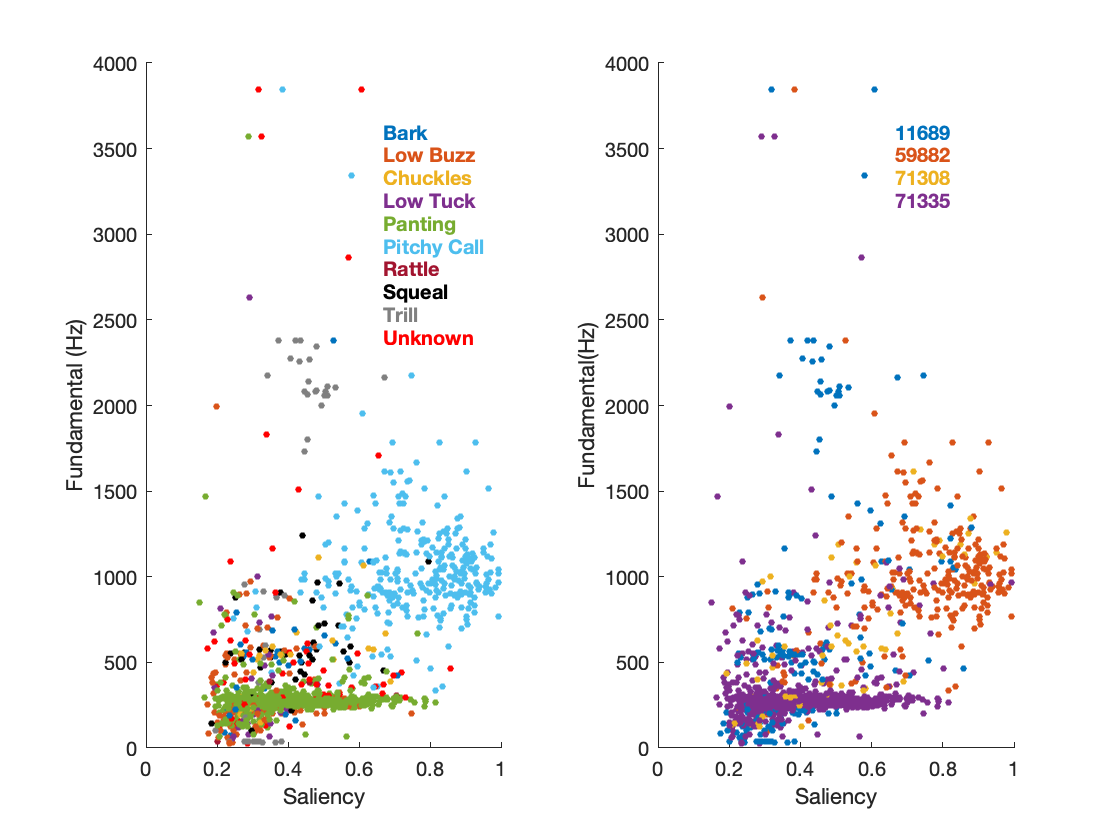

tiledlayout(1,2)
nexttile
scatter(Sal_mean, F0_mean,12,CCT,"filled")
xlabel('Saliency')
ylabel('Fundamental (Hz)')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Sal_mean, F0_mean,12,CBat,"filled")
xlabel('Saliency')
ylabel('Fundamental(Hz)')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

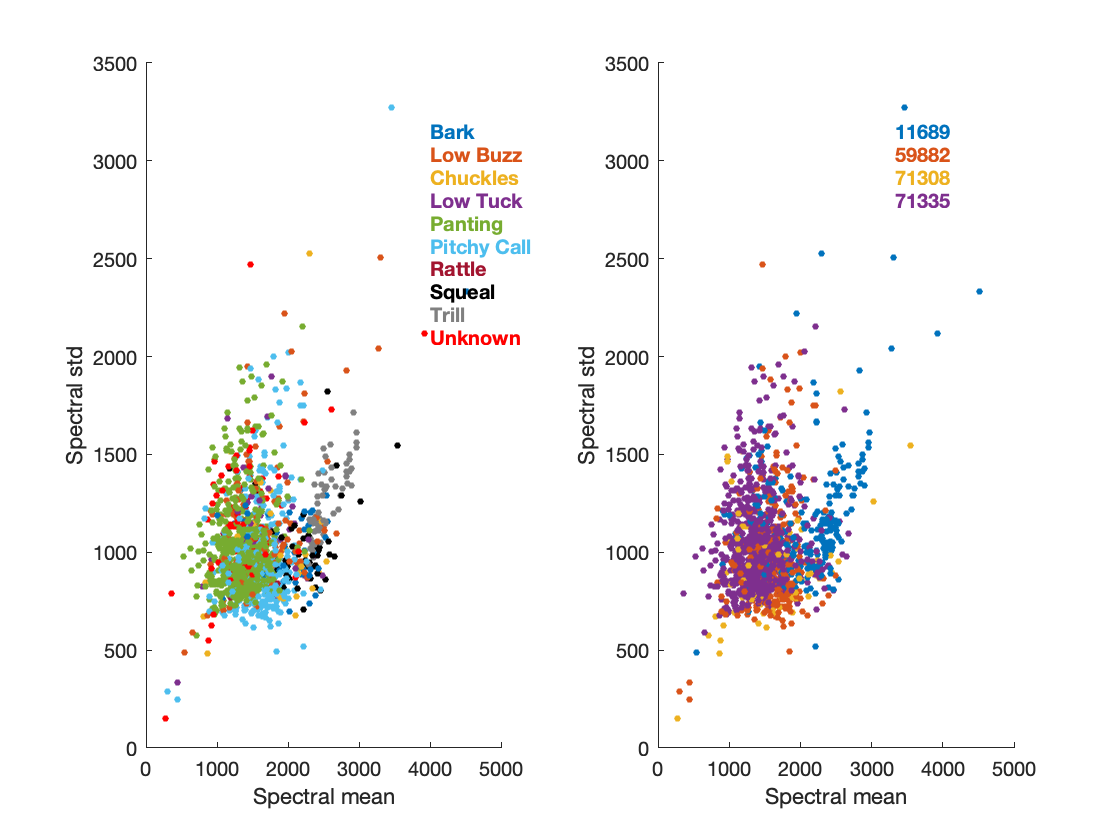

tiledlayout(1,2)
nexttile
scatter(Spect_mean, Spect_std,12,CCT,"filled")
xlabel('Spectral mean')
ylabel('Spectral std')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*4/5+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Spect_mean, Spect_std,12,CBat,"filled")
xlabel('Spectral mean')
ylabel('Spectral std')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

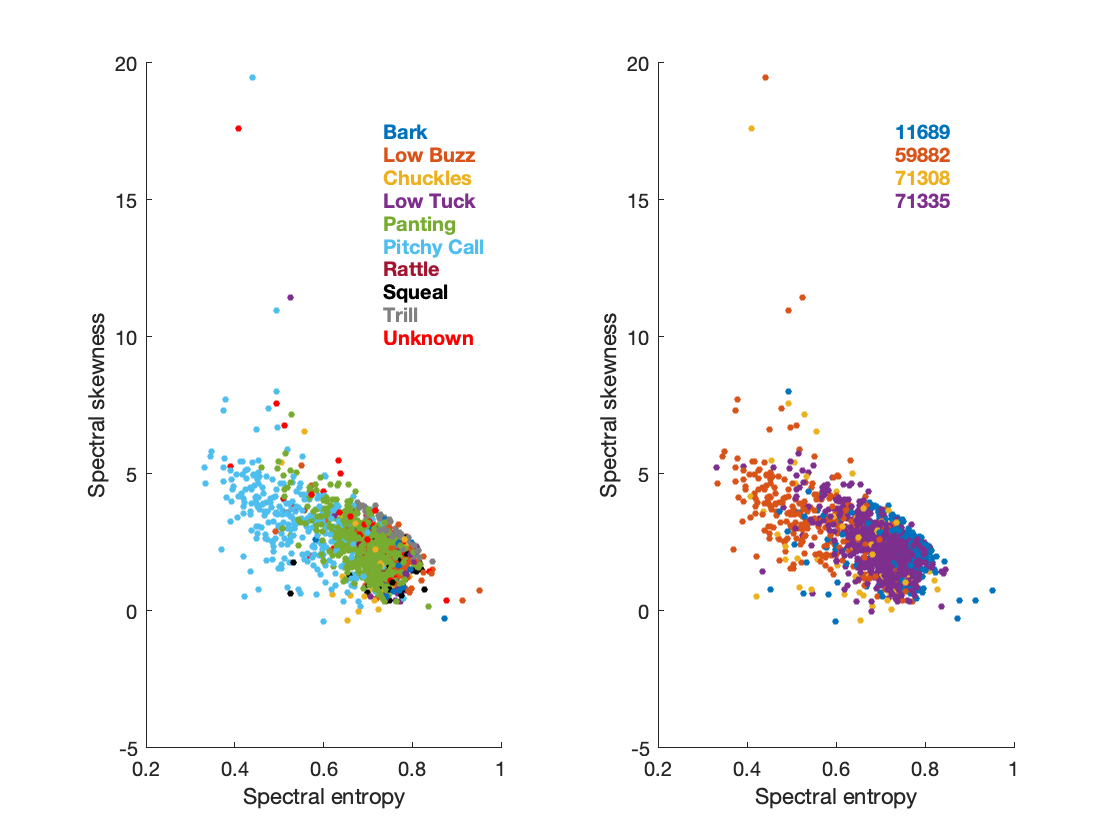

tiledlayout(1,2)
nexttile
scatter(Spect_ent, Spect_skew,12,CCT,"filled")
xlabel('Spectral entropy')
ylabel('Spectral skewness')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Spect_ent, Spect_skew,12,CBat,"filled")
xlabel('Spectral entropy')
ylabel('Spectral skewness')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

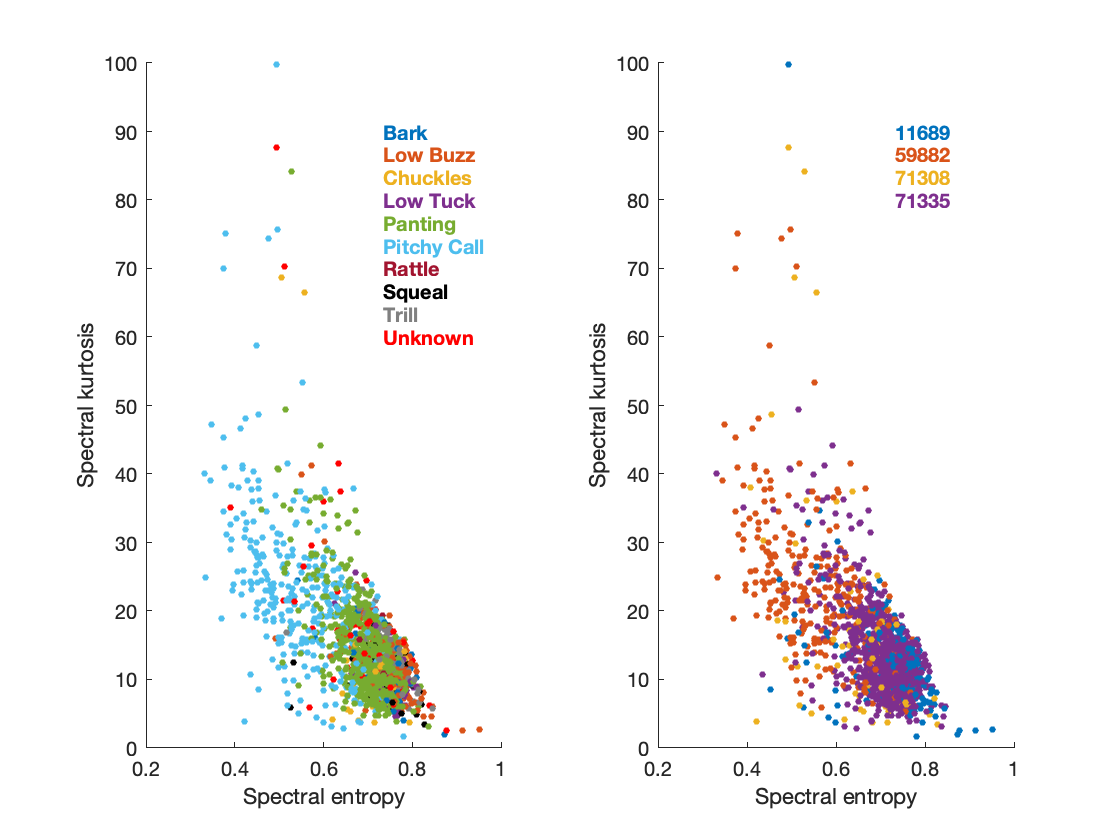

tiledlayout(1,2)
nexttile
scatter(Spect_ent, Spect_kurt,12,CCT,"filled")
xlabel('Spectral entropy')
ylabel('Spectral kurtosis')
YLim = [0 100];set(gca, 'ylim',YLim);
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Spect_ent, Spect_kurt,12,CBat,"filled")
xlabel('Spectral entropy')
ylabel('Spectral kurtosis')
YLim = [0 100];set(gca, 'ylim', YLim);
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

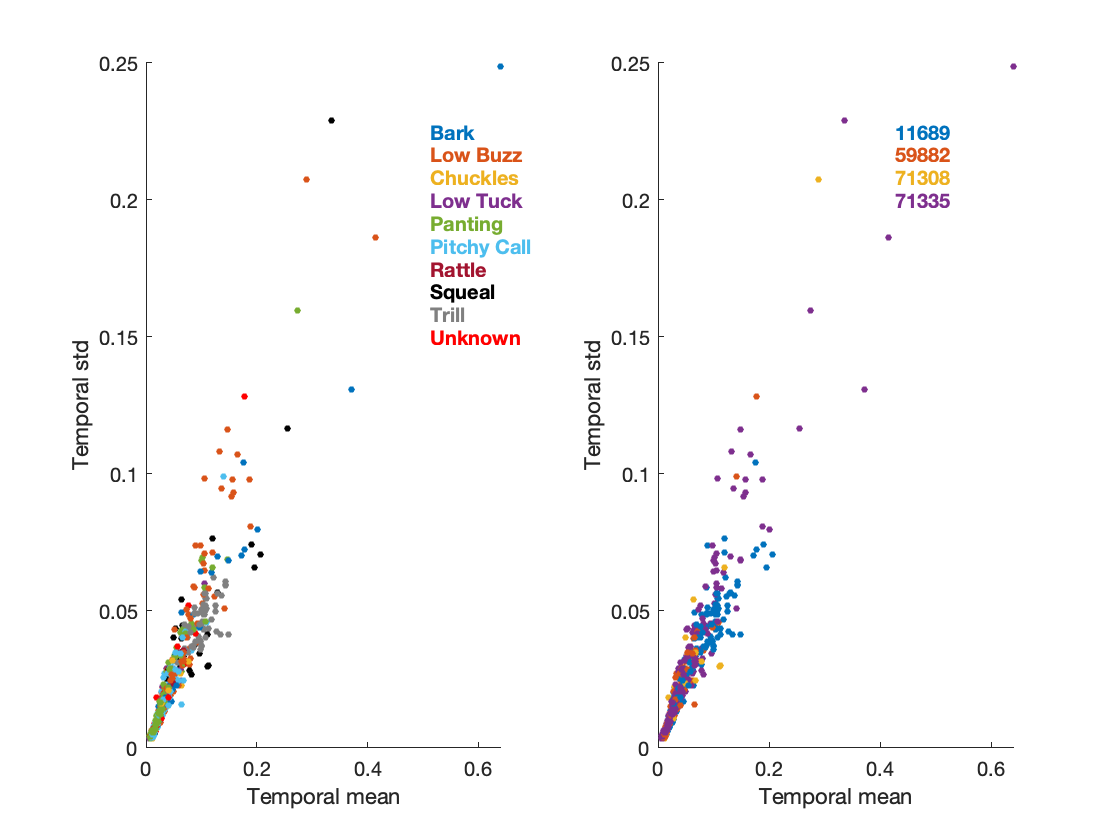

tiledlayout(1,2)
nexttile
scatter(Time_mean, Time_std,12,CCT,"filled")
xlabel('Temporal mean')
ylabel('Temporal std')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*4/5+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Time_mean, Time_std,12,CBat,"filled")
xlabel('Temporal mean')
ylabel('Temporal std')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

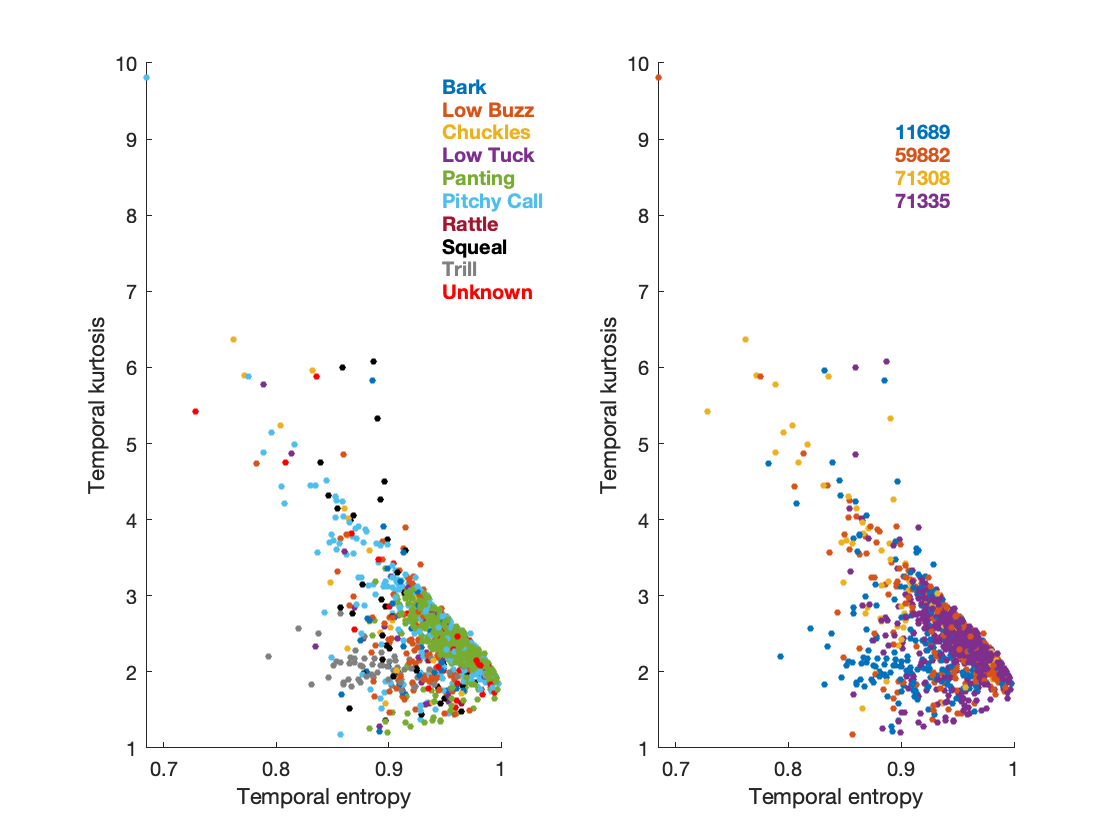

tiledlayout(1,2)
nexttile
scatter(Time_ent, Time_kurt,12,CCT,"filled")
xlabel('Temporal entropy')
ylabel('Temporal kurtosis')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*5/6+XLim(1),YLim(2)-diff(YLim)*(ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Time_ent, Time_kurt,12,CBat,"filled")
xlabel('Temporal entropy')
ylabel('Temporal kurtosis')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

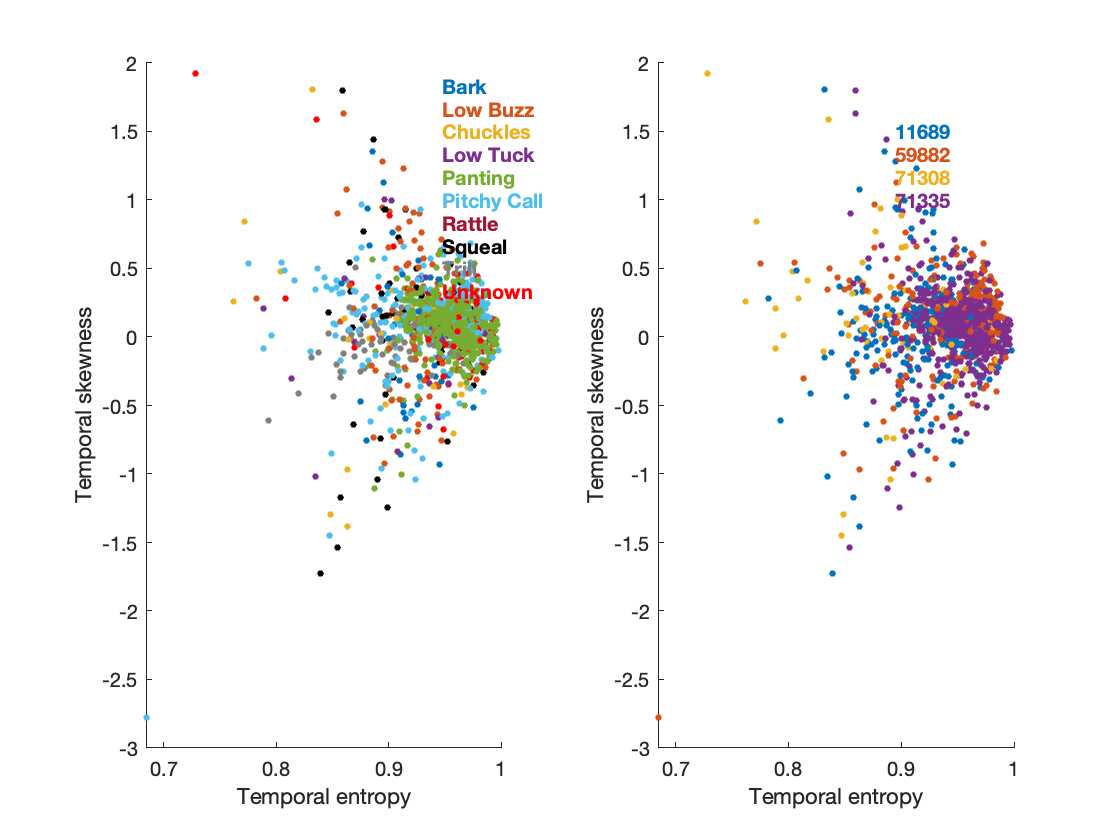

tiledlayout(1,2)
nexttile
scatter(Time_ent, Time_skew,12,CCT,"filled")
xlabel('Temporal entropy')
ylabel('Temporal skewness')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*5/6+XLim(1),YLim(2)-diff(YLim)*(ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Time_ent, Time_skew,12,CBat,"filled")
xlabel('Temporal entropy')
ylabel('Temporal skewness')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

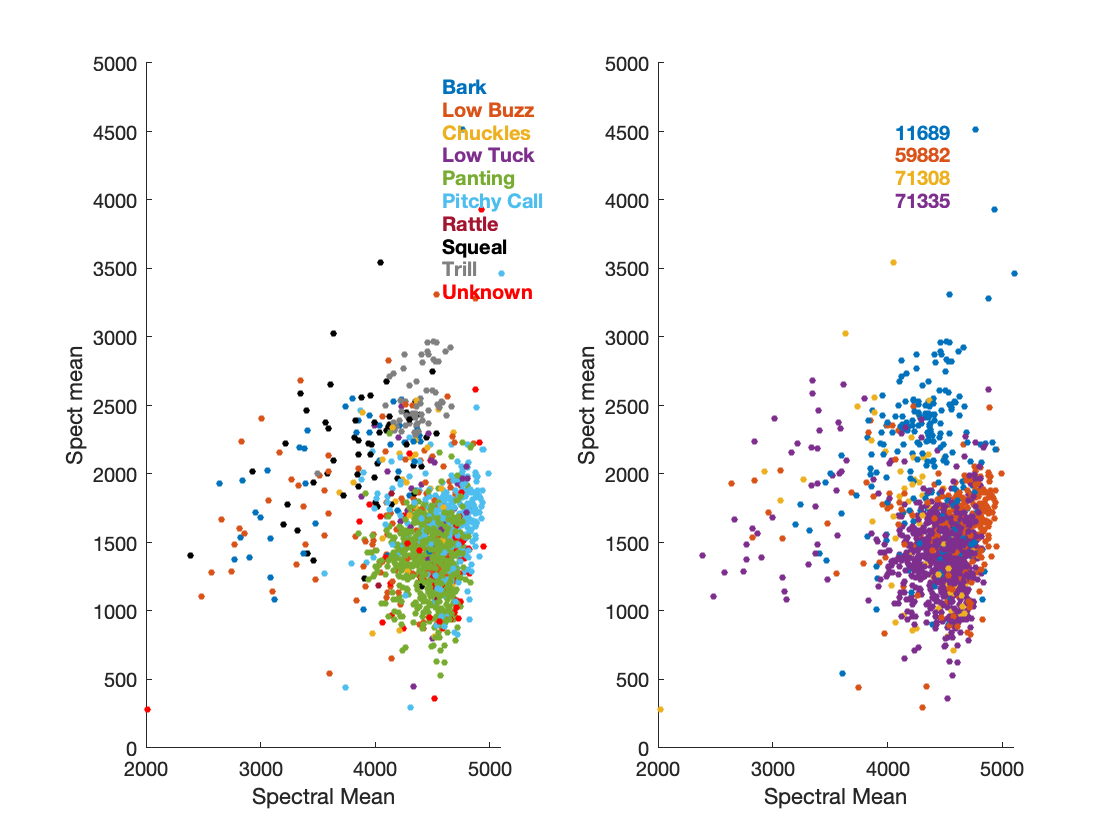

tiledlayout(1,2)
nexttile
scatter(SpectralMean_mean, Spect_mean,12,CCT,"filled")
xlabel('Spectral Mean')
ylabel('Spect mean')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*5/6+XLim(1),YLim(2)-diff(YLim)*(ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(SpectralMean_mean, Spect_mean,12,CBat,"filled")
xlabel('Spectral Mean')
ylabel('Spect mean')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

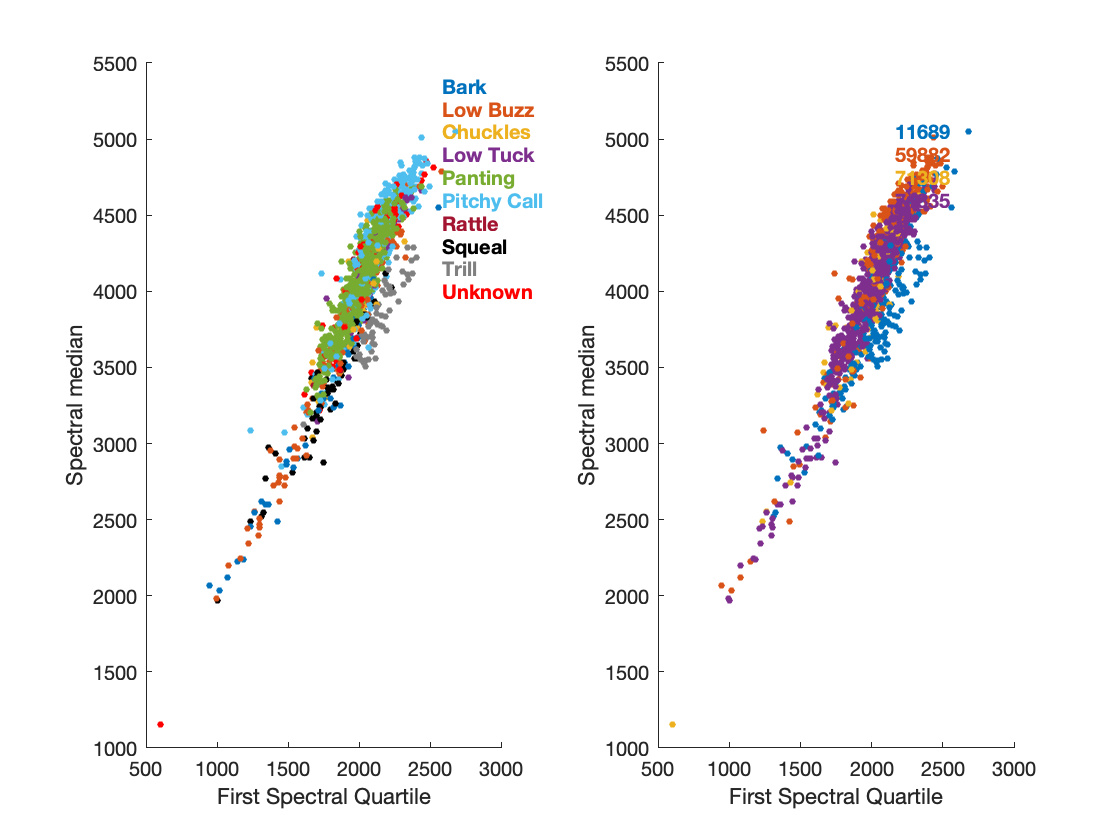

tiledlayout(1,2)
nexttile
scatter(Q1_mean, Q2_mean,12,CCT,"filled")
xlabel('First Spectral Quartile')
ylabel('Spectral median')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*5/6+XLim(1),YLim(2)-diff(YLim)*(ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Q1_mean, Q2_mean,12,CBat,"filled")
xlabel('First Spectral Quartile')
ylabel('Spectral median')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

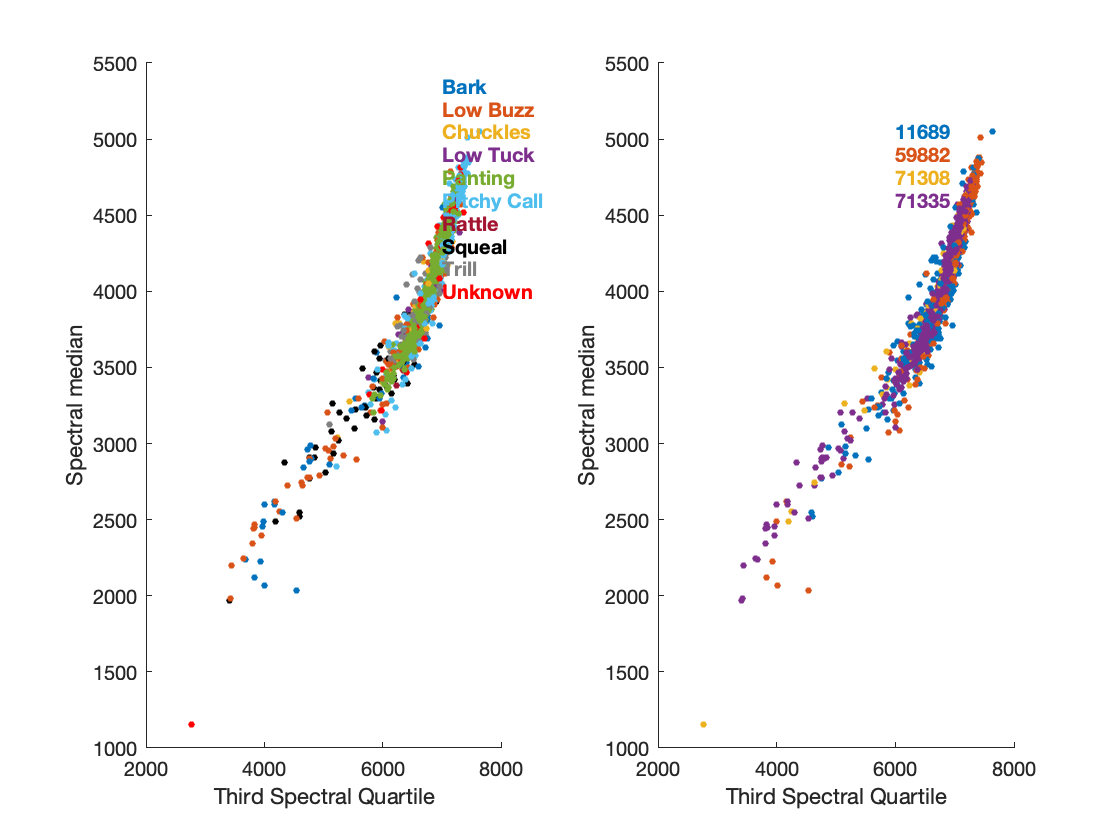

tiledlayout(1,2)
nexttile
scatter(Q3_mean, Q2_mean,12,CCT,"filled")
xlabel('Third Spectral Quartile')
ylabel('Spectral median')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UCT)
    text(diff(XLim)*5/6+XLim(1),YLim(2)-diff(YLim)*(ct)/30, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

nexttile
scatter(Q3_mean, Q2_mean,12,CBat,"filled")
xlabel('Third Spectral Quartile')
ylabel('Spectral median')
YLim = get(gca, 'ylim');
XLim = get(gca, 'xlim');
for ct=1:length(UBat)
    text(diff(XLim)*2/3+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, UBat(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end

## Plot the average MPS for each call category

First get the MPS table where each MPS is only represented once (for the calls belonging to the same sequence we have a unique shared MPS)

UID = unique(VocUID);
MPSU = nan(length(UID), size(MPS,2));
CallTypeU = cell(length(UID), 1);
BatIDU = cell(length(UID), 1);
for vv = 1:length(UID)
    Ind = find(VocUID==UID(vv),1);
    MPSU(vv,:) = MPS(Ind,:);
    CallTypeU{vv} = CallType{Ind};
    BatIDU{vv} = BatID{Ind};
    clear Ind
end

CCTU = nan(length(CallTypeU),3);
for ct=1:length(UCT)
    CCTU(contains(CallTypeU,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallTypeU,UCT(ct))),1);
end

First average MPS over all call

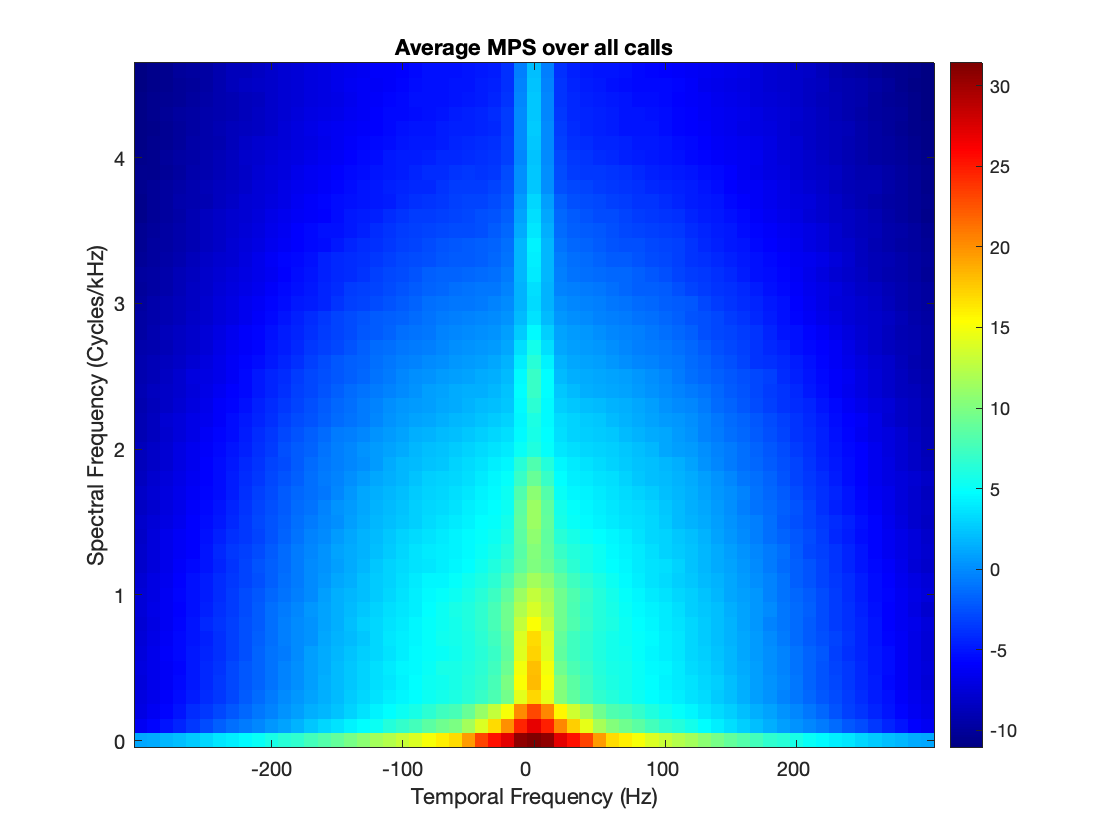

tiledlayout(1,1)
MPS_mean = reshape(mean(MPSU)',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_mean, MPS_wf, MPS_wt);
title('Average MPS over all calls')

Now average MPS for Trills

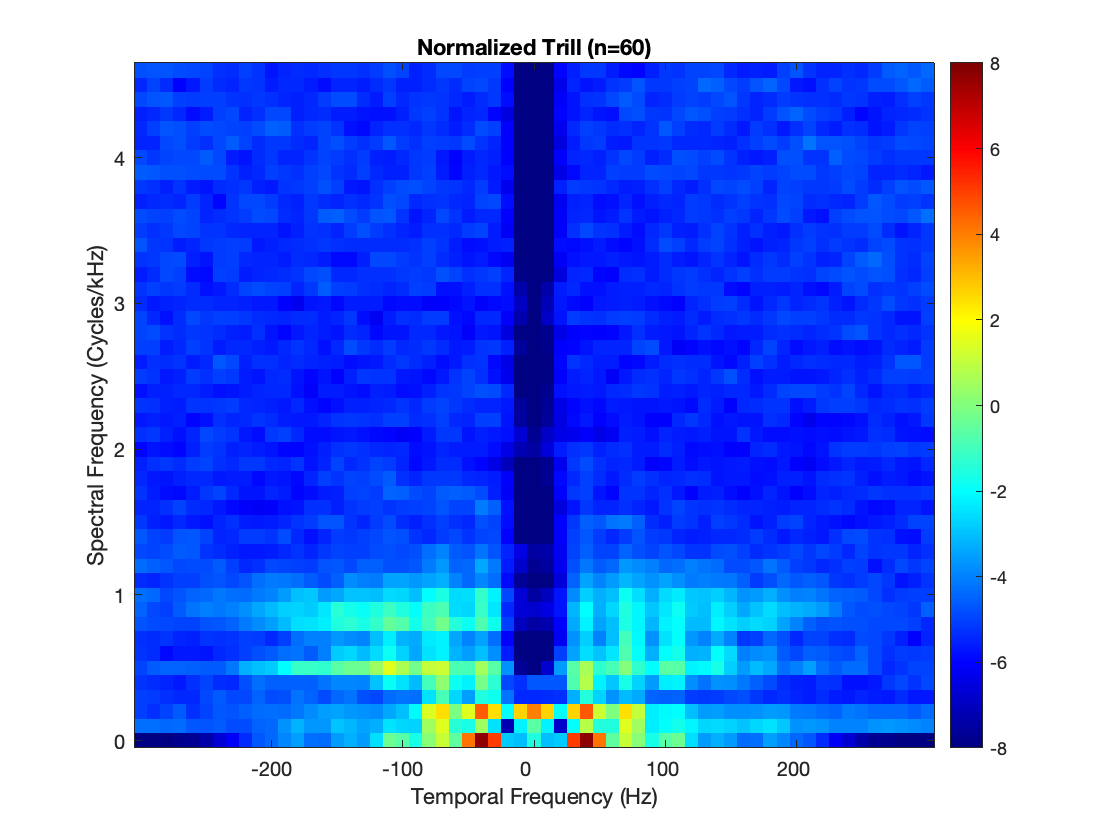

Ind = strcmp(CallTypeU, 'Tr');
MPS_Trill = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Trill./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
title(sprintf('Normalized Trill (n=%d)', sum(Ind)))

Now average MPS for Pitchy calls

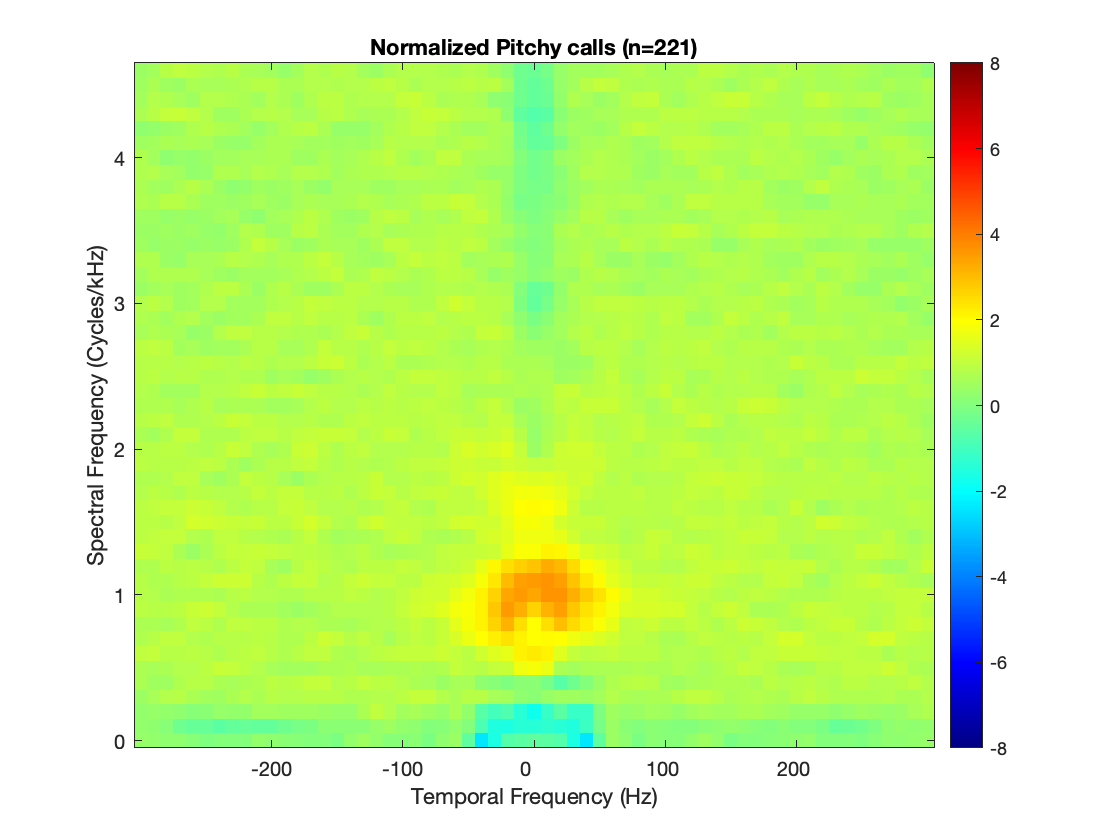

Ind = strcmp(CallTypeU, 'Pi');
MPS_Pi = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Pi./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
title(sprintf('Normalized Pitchy calls (n=%d)', sum(Ind)))

Now average MPS for Barks

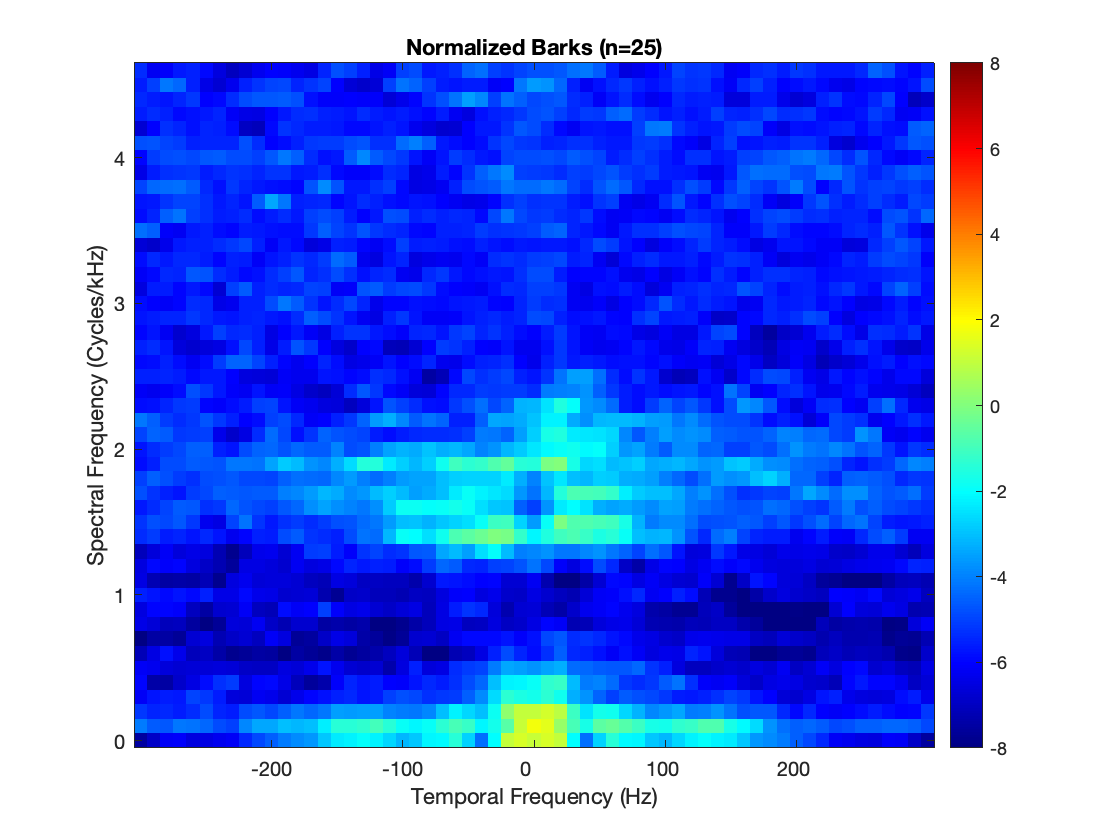

Ind = strcmp(CallTypeU, 'Ba');
MPS_Ba = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Ba./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
title(sprintf('Normalized Barks (n=%d)', sum(Ind)))

Now average MPS for Squeals

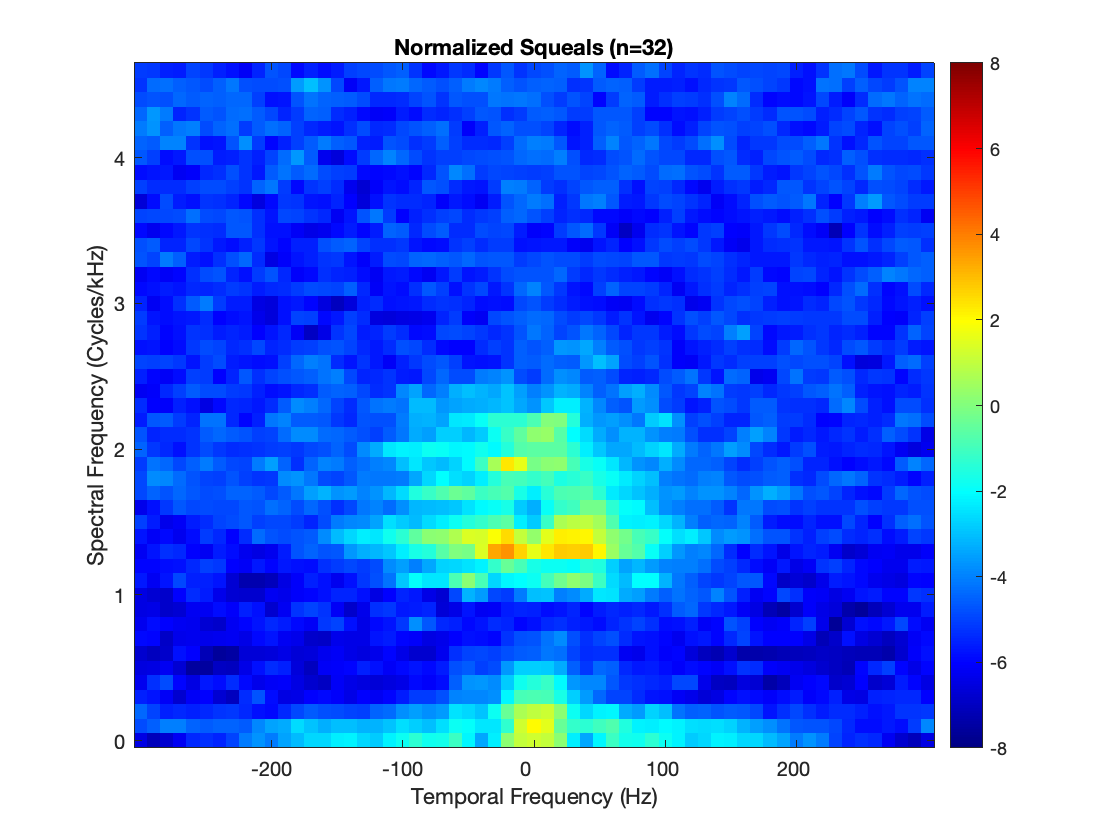

Ind = strcmp(CallTypeU, 'Sq');
MPS_Sq = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Sq./MPS_mean, MPS_wf, MPS_wt,60, [-8 8]);
title(sprintf('Normalized Squeals (n=%d)', sum(Ind)))

Now average MPS for Low Buzz

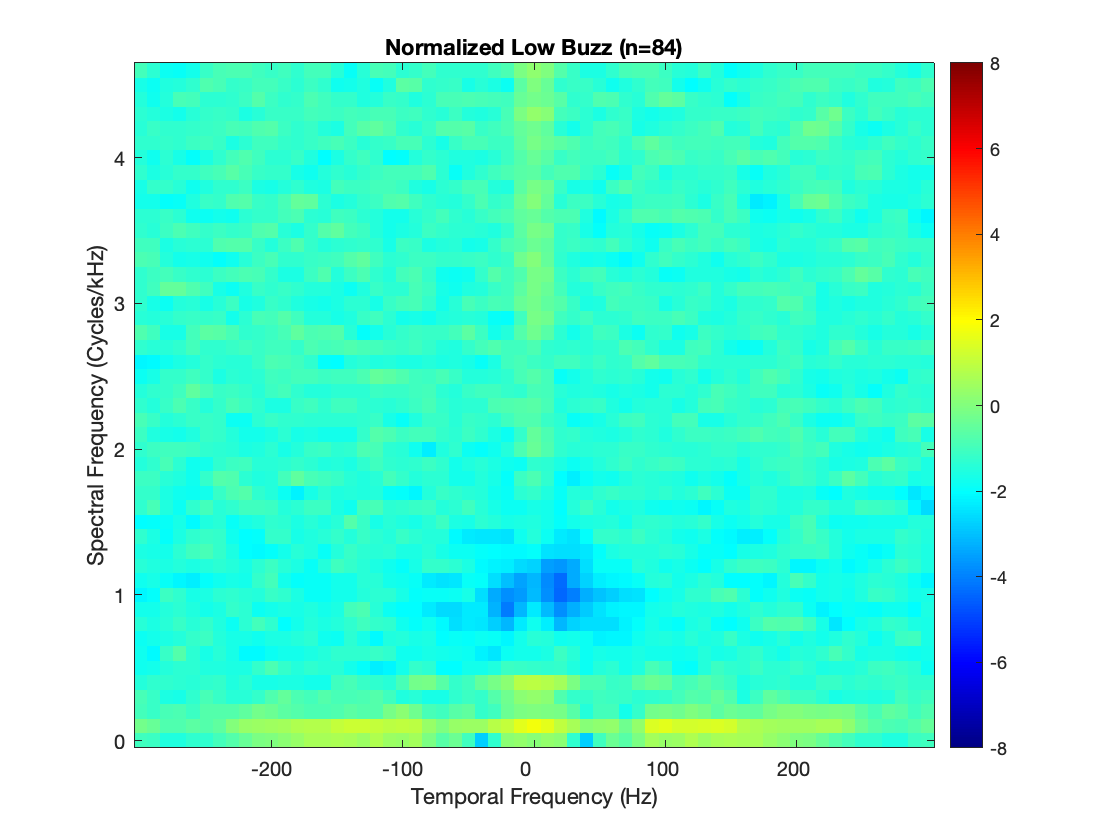

Ind = strcmp(CallTypeU, 'Bu');
MPS_Bu = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Bu./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
title(sprintf('Normalized Low Buzz (n=%d)', sum(Ind)))

Now average MPS for Panting

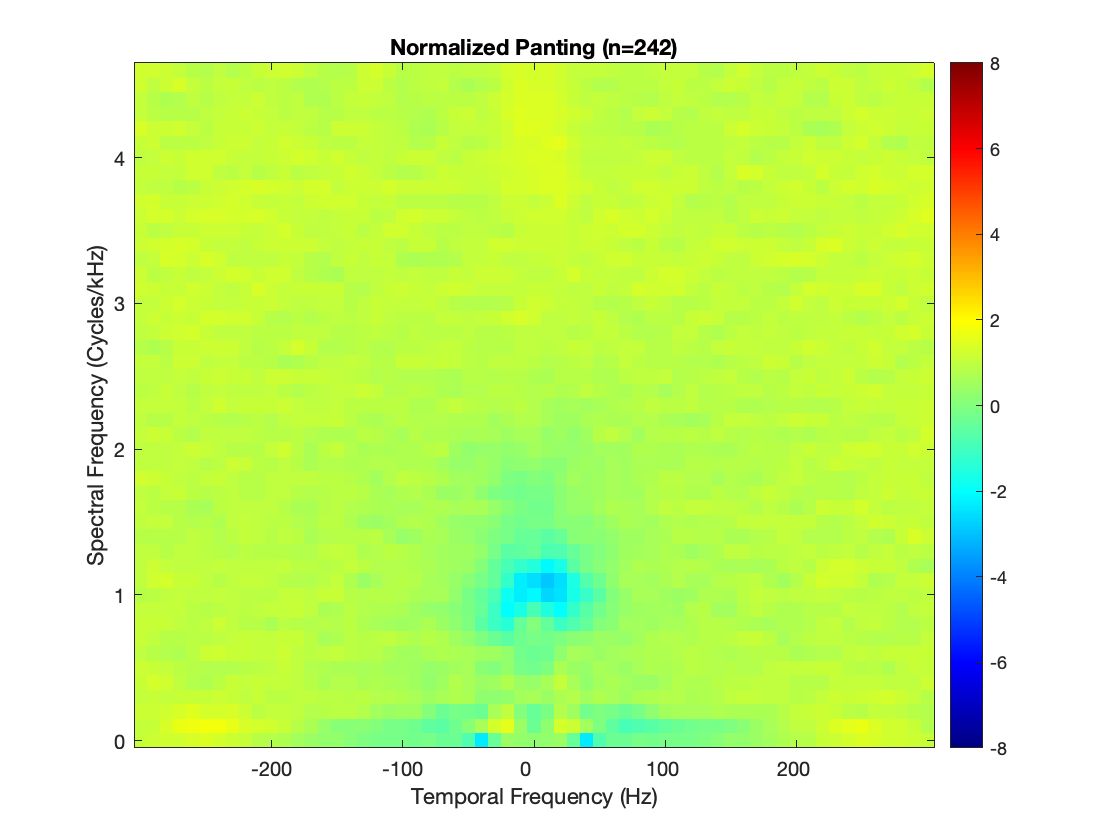

Ind = strcmp(CallTypeU, 'Pa');
MPS_Pa = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Pa./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
title(sprintf('Normalized Panting (n=%d)', sum(Ind)))

Now average MPS for Low Tuck

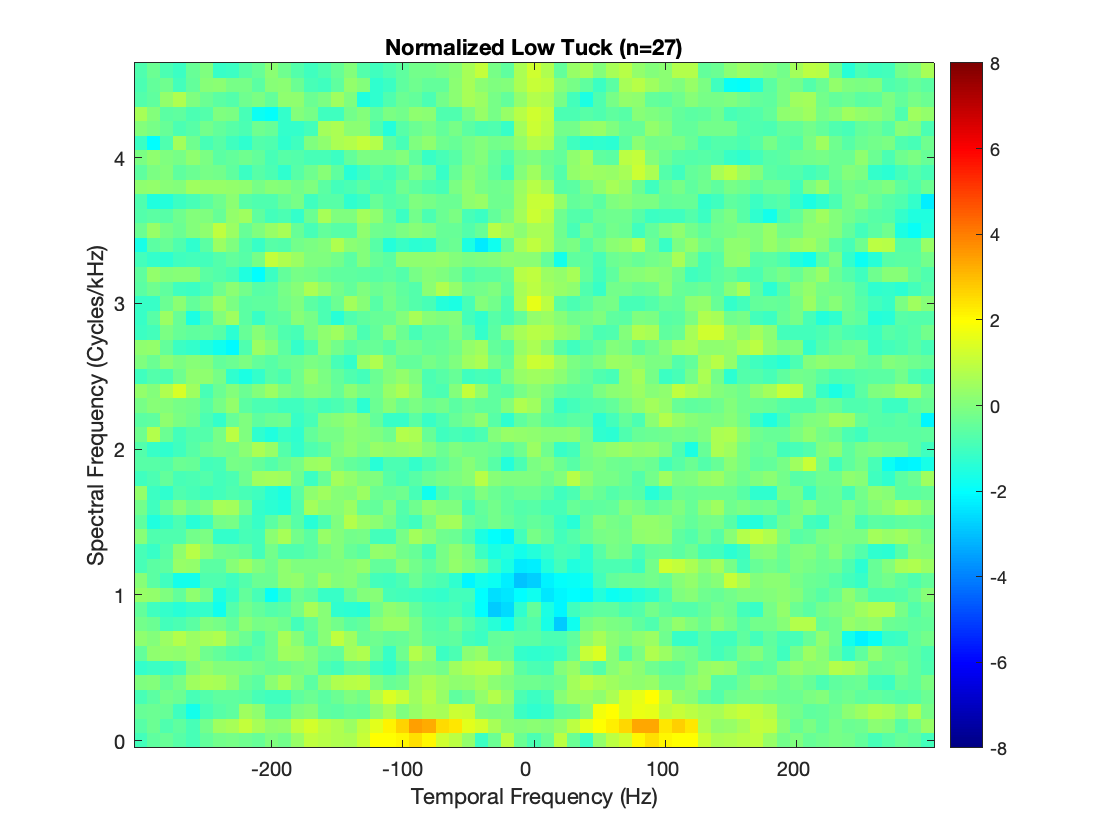

Ind = strcmp(CallTypeU, 'LT');
MPS_Ra = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Ra./MPS_mean, MPS_wf, MPS_wt,60, [-8 8]);
title(sprintf('Normalized Low Tuck (n=%d)', sum(Ind)))

Now average MPS for Chuckles

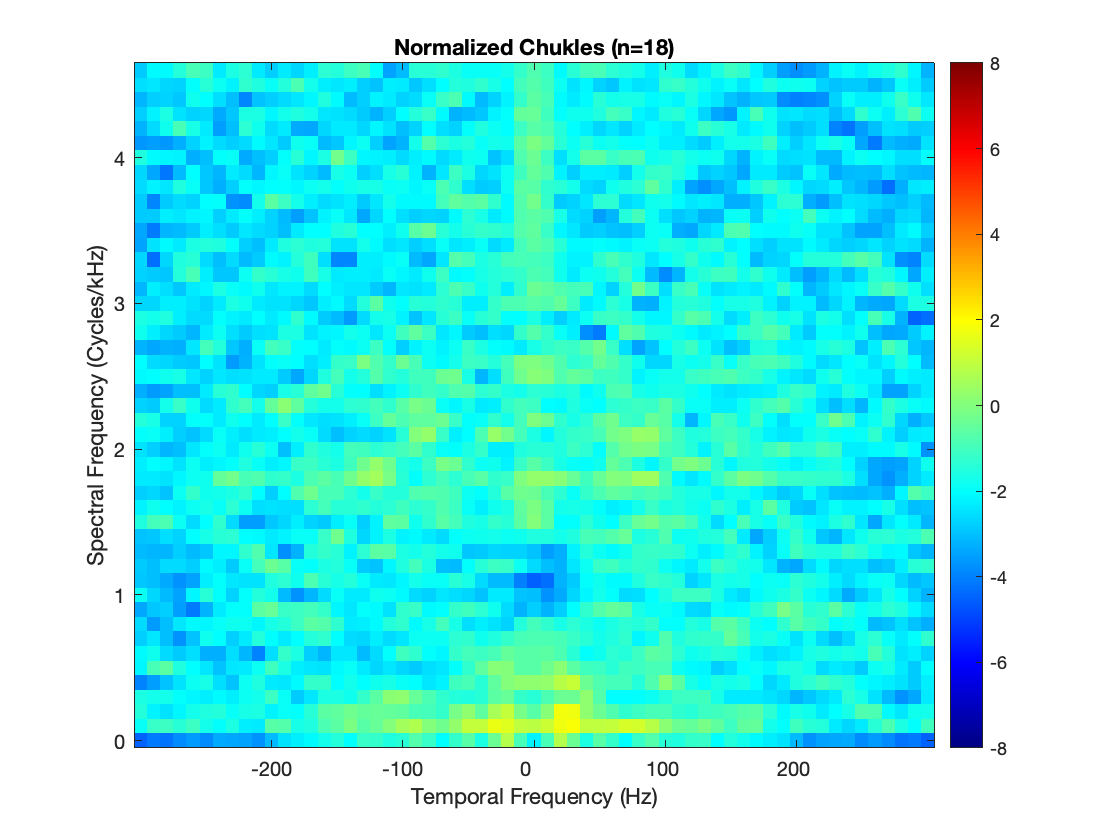

Ind = strcmp(CallTypeU, 'Ch');
MPS_Ch = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Ch./MPS_mean, MPS_wf, MPS_wt,60, [-8 8]);
title(sprintf('Normalized Chukles (n=%d)', sum(Ind)))

Now average MPS for Rattle

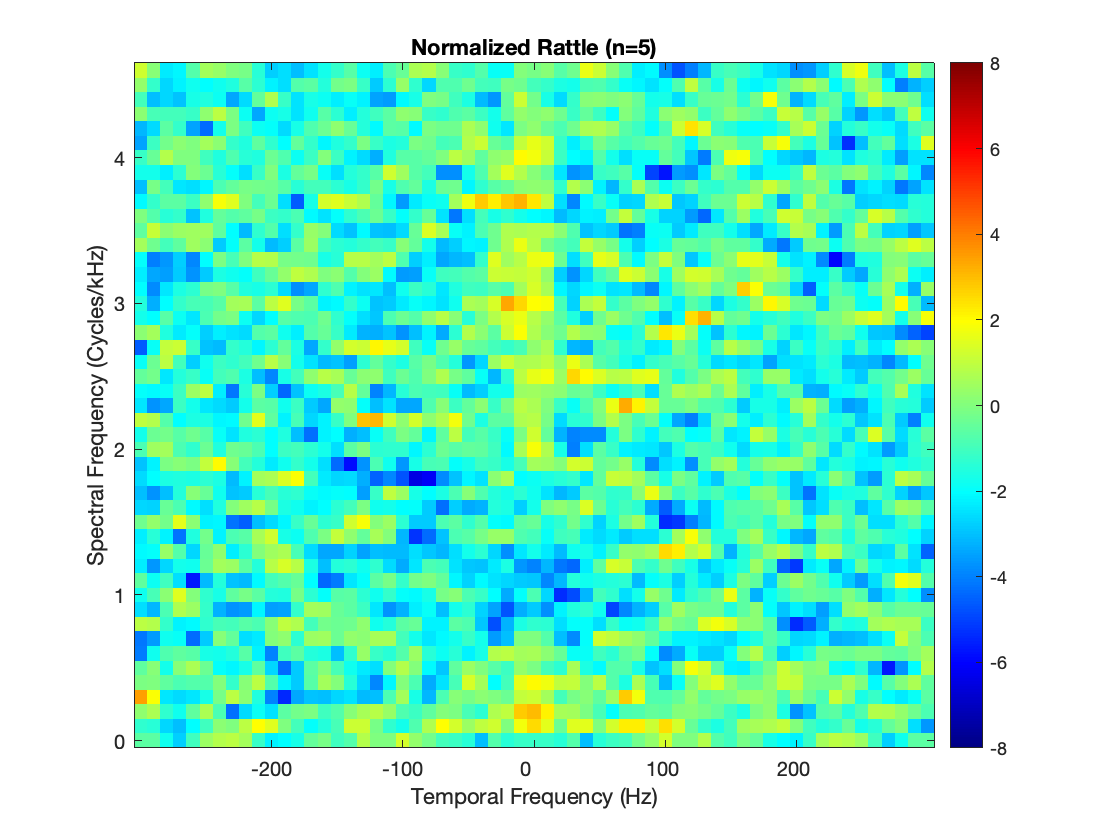

Ind = strcmp(CallTypeU, 'Ra');
MPS_Ra = reshape(mean(MPSU(Ind,:))',length(MPS_wf), length(MPS_wt));
plot_mps(MPS_Ra./MPS_mean, MPS_wf, MPS_wt,60, [-8 8]);
title(sprintf('Normalized Rattle (n=%d)', sum(Ind)))

# Project Normalized MPS in UMAP space

First restrict the MPS spectral frequency to 3 cycles/kHz and normalized all MPS

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = size(MPSU,1);
MPS_norm = cell(1,NVoc);
MPSU_focus = cell(1,NVoc);
for vv=1:NVoc
    MPS_local = reshape(MPSU(vv,:)',length(MPS_wf), length(MPS_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_norm{vv} = reshape(MPS_local./MPS_mean(IndWf,:), numel(MPS_local),1);
    MPSU_focus{vv} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_norm = [MPS_norm{:}]';
MPSU_focus = [MPSU_focus{:}]';

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

% default parameters
NNeigh = 30;
MinDist = 0.3;
[Reduction,UMAP]= run_umap(MPS_norm, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',NNeigh, 'min_dist',MinDist);

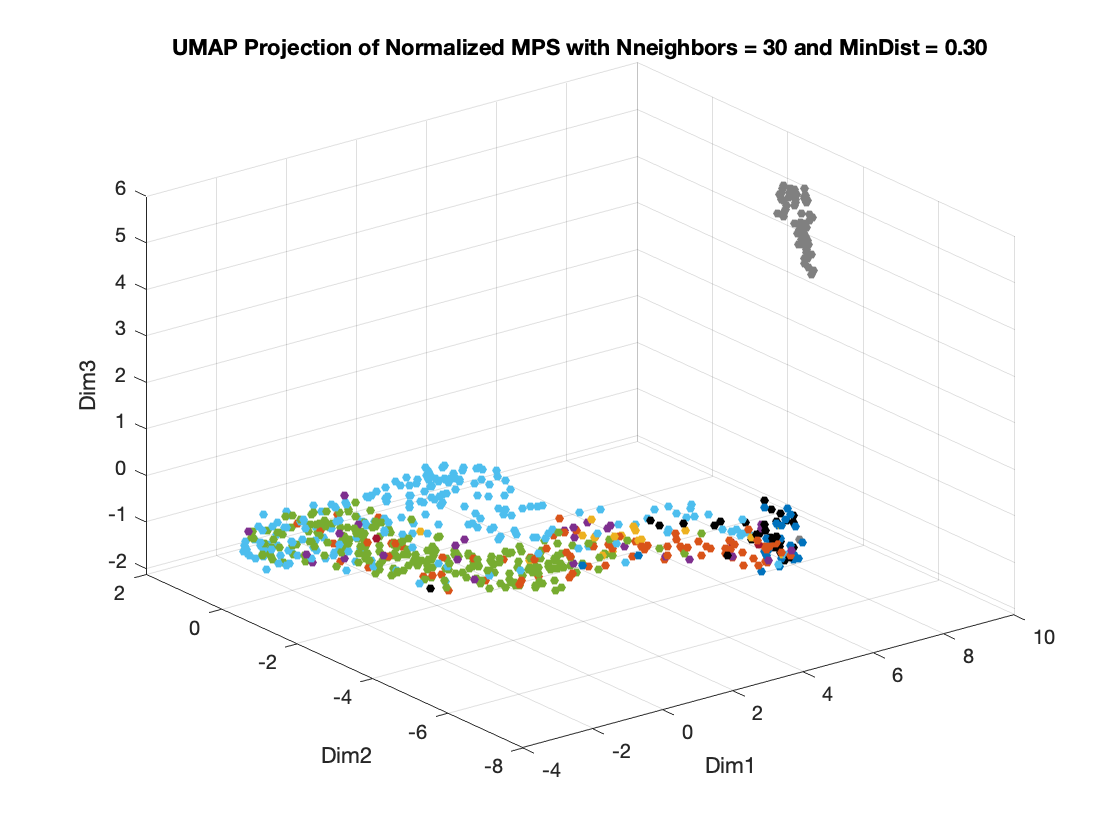

figure()
scatter3(Reduction(~strcmp(CallTypeU, 'Un'),1), Reduction(~strcmp(CallTypeU, 'Un'),2),Reduction(~strcmp(CallTypeU, 'Un'),3),20,CCTU(~strcmp(CallTypeU, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection of Normalized MPS with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% default parameters
NNeigh = 30;
MinDist = 0.3;
[Reduction,UMAP]= run_umap(MPSU_focus, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',NNeigh, 'min_dist',MinDist);

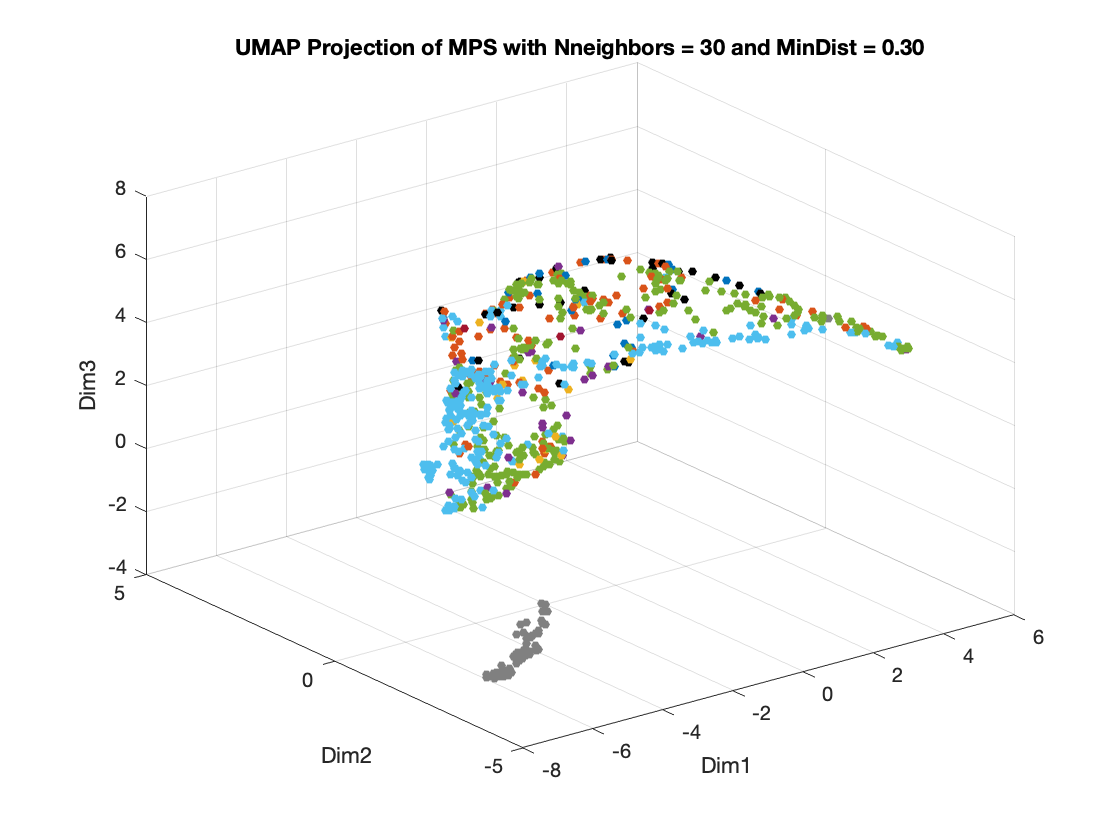

figure()
scatter3(Reduction(~strcmp(CallTypeU, 'Un'),1), Reduction(~strcmp(CallTypeU, 'Un'),2),Reduction(~strcmp(CallTypeU, 'Un'),3),20,CCTU(~strcmp(CallTypeU, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection of MPS with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% Decrease the number of neighbor to focalize more on local structure
NNeigh = 10;
MinDist = 0.3;
[Reduction,UMAP]= run_umap(MPS_norm, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',NNeigh, 'min_dist',MinDist);

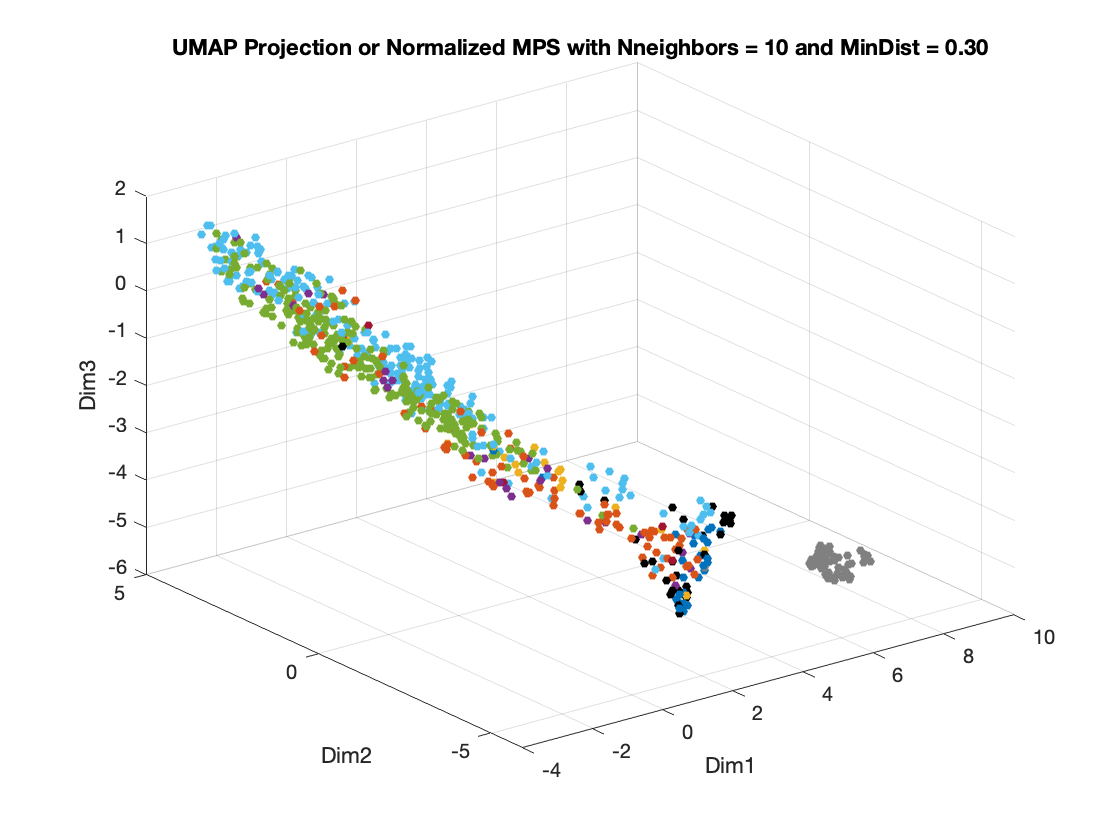

figure()
scatter3(Reduction(~strcmp(CallTypeU, 'Un'),1), Reduction(~strcmp(CallTypeU, 'Un'),2),Reduction(~strcmp(CallTypeU, 'Un'),3),20,CCTU(~strcmp(CallTypeU, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection or Normalized MPS with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% Increase Min Dist to decrease density
NNeigh = 10;
MinDist = 0.5;
[Reduction,UMAP]= run_umap(MPS_norm, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',NNeigh, 'min_dist',MinDist);


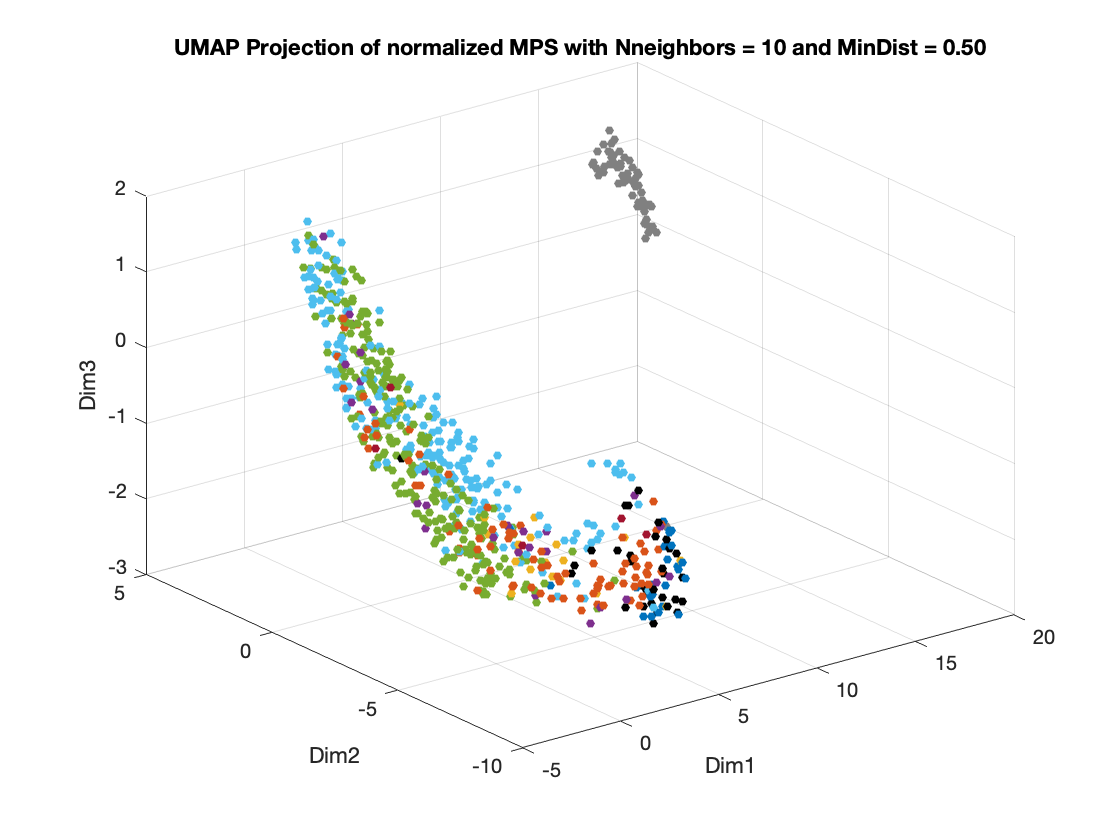

figure()
scatter3(Reduction(~strcmp(CallTypeU, 'Un'),1), Reduction(~strcmp(CallTypeU, 'Un'),2),Reduction(~strcmp(CallTypeU, 'Un'),3),20,CCTU(~strcmp(CallTypeU, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection of normalized MPS with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% Decrease Min Dist to increase density
NNeigh = 10;
MinDist = 0.051;
[Reduction,UMAP]= run_umap(MPS_norm, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',NNeigh, 'min_dist',MinDist);

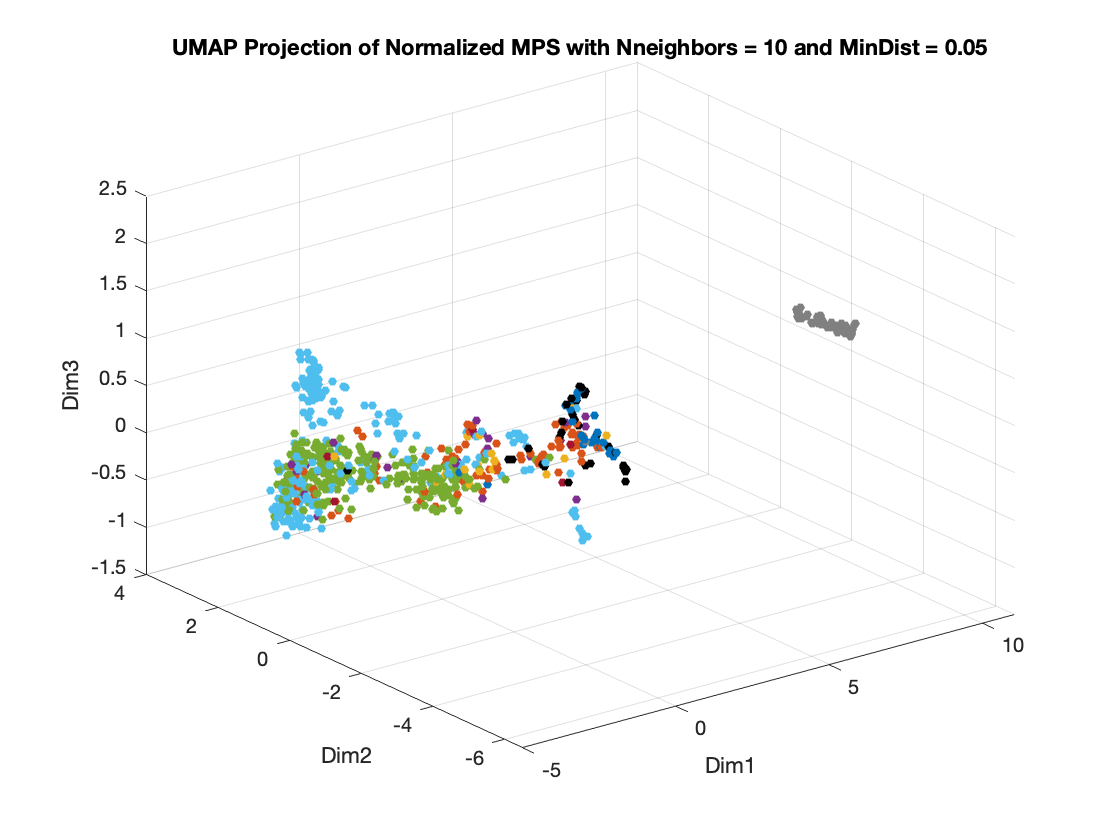

figure()
scatter3(Reduction(~strcmp(CallTypeU, 'Un'),1), Reduction(~strcmp(CallTypeU, 'Un'),2),Reduction(~strcmp(CallTypeU, 'Un'),3),20,CCTU(~strcmp(CallTypeU, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection of Normalized MPS with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% Decrease Min Dist to increase density
NNeigh = 10;
MinDist = 0.051;
[Reduction,UMAP]= run_umap(MPSU_focus, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',NNeigh, 'min_dist',MinDist);

figure()
scatter3(Reduction(~strcmp(CallTypeU, 'Un'),1), Reduction(~strcmp(CallTypeU, 'Un'),2),Reduction(~strcmp(CallTypeU, 'Un'),3),20,CCTU(~strcmp(CallTypeU, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection of MPS with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% Increase the number of neighbor to focalize more on global structure
NNeigh = 50;
MinDist = 0.051;
[Reduction,UMAP]= run_umap(MPS_norm, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',NNeigh, 'min_dist',MinDist);

figure()
scatter3(Reduction(~strcmp(CallTypeU, 'Un'),1), Reduction(~strcmp(CallTypeU, 'Un'),2),Reduction(~strcmp(CallTypeU, 'Un'),3),20,CCTU(~strcmp(CallTypeU, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection of Normalized MPS with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% Try directly the MPS as an input instead of the normalized MPS
NNeigh = 50;
MinDist = 0.051;
[Reduction,UMAP]= run_umap(MPSU_focus, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',NNeigh, 'min_dist',MinDist);

figure()
scatter3(Reduction(~strcmp(CallTypeU, 'Un'),1), Reduction(~strcmp(CallTypeU, 'Un'),2),Reduction(~strcmp(CallTypeU, 'Un'),3),20,CCTU(~strcmp(CallTypeU, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection of MPS with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

# Hierarchical clustering of vocalizations 

First decide of an optimal representation for the MPS by using UMAP as a dimensionality reduction

To inquire on the number of diemsions that might correctly capture the data, let's run a PCA first

% 
[PC,Score,~, ~, VarExpl,~] = pca(MPS_norm);

figure()
plot(cumsum(VarExpl), 'k-','LineWidth',2);
xlabel('PC#')
ylabel('% Cumulative Variance explained')

fprintf(1,'Number of PC to reach 90%% of variance = %d\n', find(cumsum(VarExpl)>90,1))

Number of PC to reach 90% of variance = 278


fprintf(1,'******    Normalized MPS   ***********\n')

******    Normalized MPS   ***********


[Reduction,UMAP]= run_umap(MPS_norm, 'metric','euclidean','n_component',50,'target_weight',0.55, 'n_neighbors',50, 'min_dist',0.051);

% Obtain matrix of reduction MPS values for all vocal elements
MPSReduction = nan(length(VocUID), 50);
for vv=1:length(VocUID)
    MPSReduction(vv,:) = Reduction(UID==VocUID(vv),:);
end

% Only using MPS
Z = linkage( MPSReduction,'ward','euclidean');
[D1, T1, ~] = dendrogram(Z,0, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

ClustSize = 2:9;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSReduction,T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSReduction, 'linkage','CalinskiHarabasz','KList',1:15) %9 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 1323
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 1.9271e+03 2.5606e+03 3.5629e+03 4.5799e+03 5.3946e+03 5.7351e+03 6.4943e+03 7.0512e+03 7.0227e+03 6.8312e+03 6.6828e+03 6.4479e+03 6.2688e+03 6.1270e+03]
           OptimalK: 9


eva = evalclusters(MPSReduction, 'linkage','DaviesBouldin','KList',1:9) % 4 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 1323
         InspectedK: [1 2 3 4 5 6 7 8 9]
    CriterionValues: [NaN 0.5888 0.6655 0.4746 0.5721 0.6278 0.6369 0.6232 0.7115]
           OptimalK: 4


eva = evalclusters(MPSReduction, 'linkage','silhouette','KList',1:9) %2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 1323
         InspectedK: [1 2 3 4 5 6 7 8 9]
    CriterionValues: [NaN 0.7610 0.6558 0.6629 0.6391 0.6020 0.5852 0.6413 0.6202]
           OptimalK: 2


figure()
t=tiledlayout(1,2);
CTin9Cluster = nan(10,10);
nexttile
[D9, T9, ~] = dendrogram(Z,9, 'ColorThreshold','Default','Orientation','left');
set(D9,'LineWidth',2)
for cc=1:9
    for ct=1:length(UCT)
        CTin9Cluster(cc,ct) = sum(strcmp(CallType(T9==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTin9Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

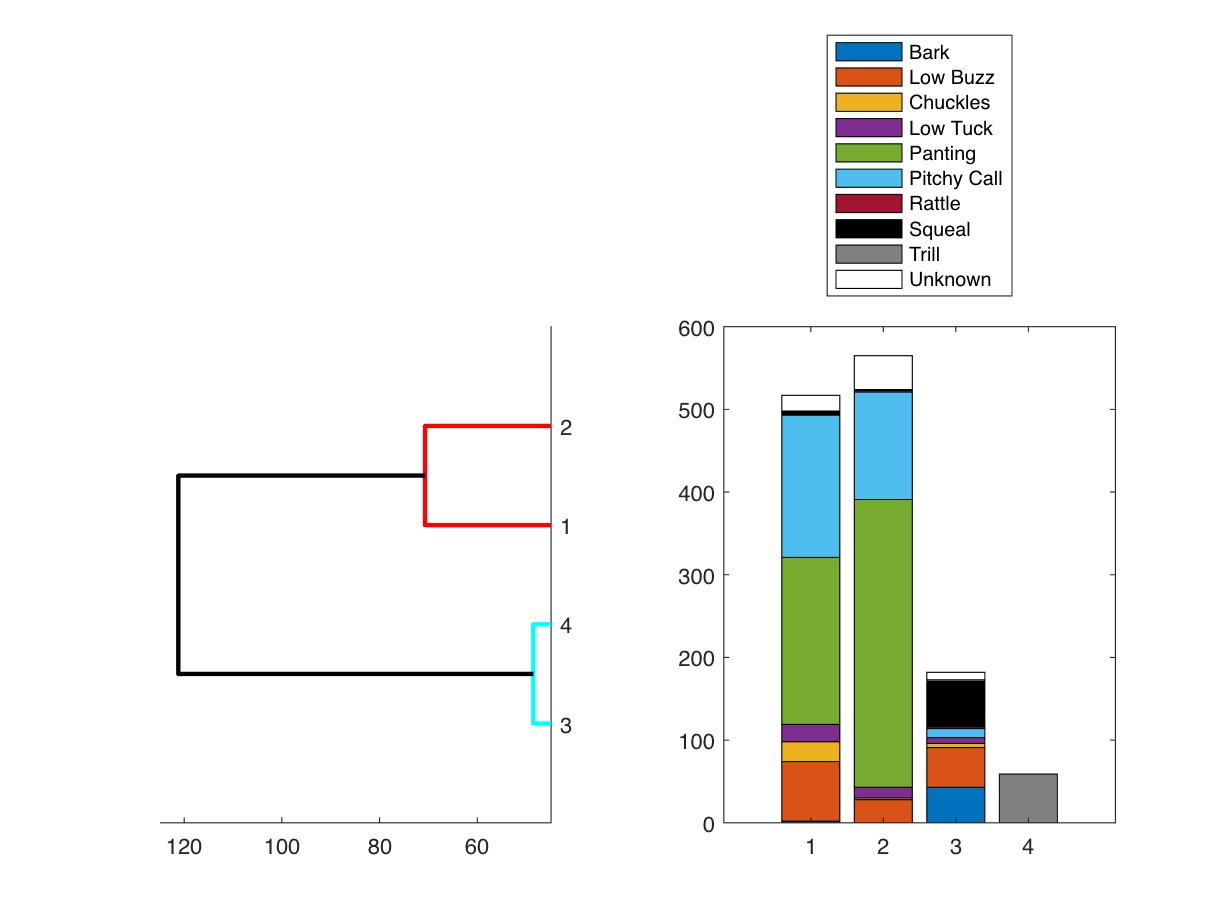

figure()
t=tiledlayout(1,2);
CTin4Cluster = nan(4,10);
nexttile
[D4, T4, ~] = dendrogram(Z,4, 'ColorThreshold','Default','Orientation','left');
set(D4,'LineWidth',2)
for cc=1:4
    for ct=1:length(UCT)
        CTin4Cluster(cc,ct) = sum(strcmp(CallType(T4==cc), UCT{ct}));
    end
end
nexttile
B= bar(CTin4Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

fprintf(1,'******    Raw MPS   ***********\n')

******    Raw MPS   ***********


[Reduction,UMAP]= run_umap(MPSU_focus, 'metric','euclidean','n_component',50,'target_weight',0.55, 'n_neighbors',50, 'min_dist',0.051);

% Obtain matrix of reduction MPS values for all vocal elements
MPSReduction = nan(length(VocUID), 50);
for vv=1:length(VocUID)
    MPSReduction(vv,:) = Reduction(UID==VocUID(vv),:);
end

% Only using MPS
Z = linkage( MPSReduction,'ward','euclidean');
[D1, T1, ~] = dendrogram(Z,0, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

ClustSize = 2:9;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSReduction,T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSReduction, 'linkage','CalinskiHarabasz','KList',1:30) %30 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 1323
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30]
    CriterionValues: [NaN 1.9935e+03 2.0358e+03 2.9994e+03 3.1390e+03 3.4325e+03 3.6653e+03 3.9705e+03 3.9525e+03 4.0125e+03 4.1818e+03 4.4079e+03 4.4051e+03 4.4580e+03 4.5698e+03 4.7108e+03 4.7547e+03 4.8089e+03 4.8803e+03 4.9131e+03 4.9378e+03 … ]
           OptimalK: 30


eva = evalclusters(MPSReduction, 'linkage','DaviesBouldin','KList',1:9) % 3 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 1323
         InspectedK: [1 2 3 4 5 6 7 8 9]
    CriterionValues: [NaN 0.6477 0.4998 0.5824 0.5974 0.7191 0.7860 0.6776 0.6244]
           OptimalK: 3


eva = evalclusters(MPSReduction, 'linkage','silhouette','KList',1:9) %3 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 1323
         InspectedK: [1 2 3 4 5 6 7 8 9]
    CriterionValues: [NaN 0.6797 0.7510 0.7318 0.7195 0.5830 0.6013 0.6496 0.6627]
           OptimalK: 3


figure()
t=tiledlayout(1,2);
CTin9Cluster = nan(10,10);
nexttile
[D9, T9, ~] = dendrogram(Z,9, 'ColorThreshold','Default','Orientation','left');
set(D9,'LineWidth',2)
for cc=1:9
    for ct=1:length(UCT)
        CTin9Cluster(cc,ct) = sum(strcmp(CallType(T9==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTin9Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

figure()
t=tiledlayout(1,2);
CTin4Cluster = nan(4,10);
nexttile
[D4, T4, ~] = dendrogram(Z,4, 'ColorThreshold','Default','Orientation','left');
set(D4,'LineWidth',2)
for cc=1:4
    for ct=1:length(UCT)
        CTin4Cluster(cc,ct) = sum(strcmp(CallType(T4==cc), UCT{ct}));
    end
end
nexttile
B= bar(CTin4Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

figure()
t=tiledlayout(1,2);
CTin3Cluster = nan(3,10);
nexttile
[D3, T3, ~] = dendrogram(Z,3, 'ColorThreshold','Default','Orientation','left');
set(D3,'LineWidth',2)
for cc=1:3
    for ct=1:length(UCT)
        CTin3Cluster(cc,ct) = sum(strcmp(CallType(T3==cc), UCT{ct}));
    end
end
nexttile
B= bar(CTin3Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

fprintf(1,'******    PAF    ***********\n')

******    PAF    ***********


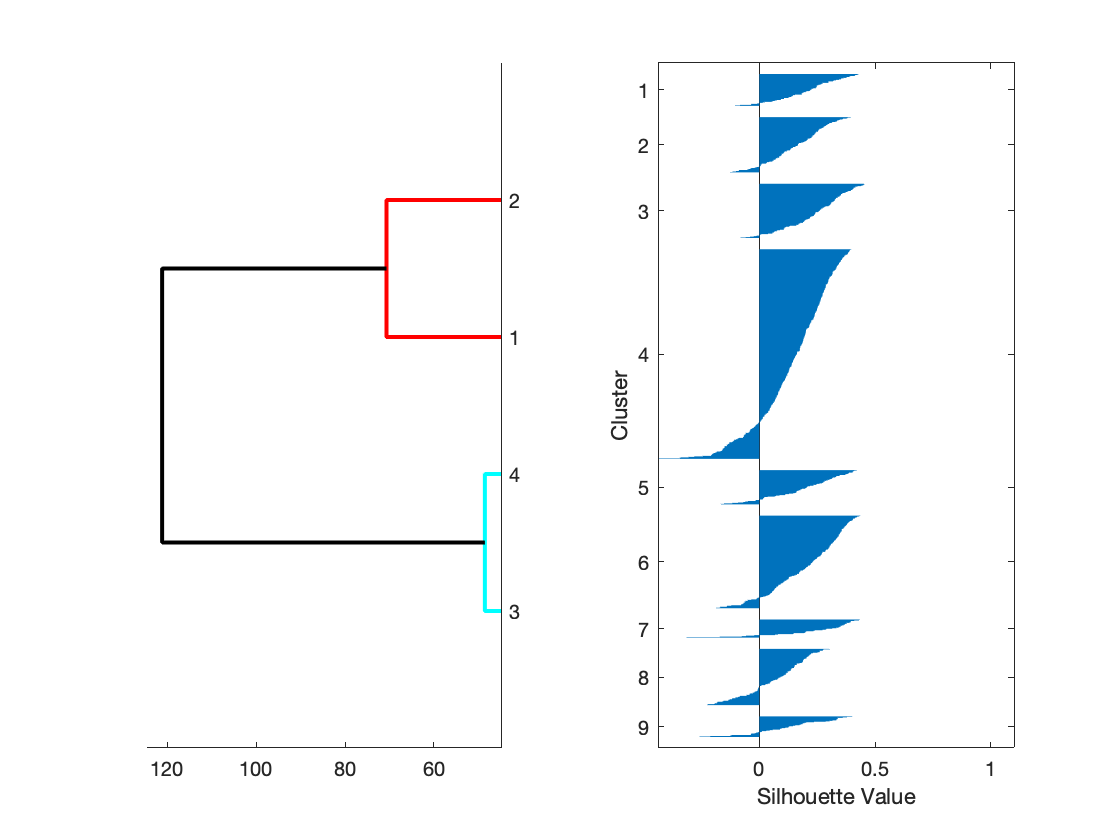

DataTable = [F0_mean Sal_mean Spect_mean Spect_std Spect_ent SpectralMean_mean Time_ent Time_kurt];
DataTable1 = zscore(DataTable(~isnan(F0_mean),:));
Z = linkage( DataTable1,'ward','euclidean');
[D1, T1, ~] = dendrogram(Z,0, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
ClustSize = 2:9;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(DataTable1,T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(DataTable1, 'linkage','CalinskiHarabasz','KList',1:9) %4 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 1170
         InspectedK: [1 2 3 4 5 6 7 8 9]
    CriterionValues: [NaN 265.2516 282.6368 253.7603 234.5296 224.8394 216.5024 213.4143 206.5356]
           OptimalK: 3


eva = evalclusters(DataTable1, 'linkage','DaviesBouldin','KList',1:9) % 4 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 1170
         InspectedK: [1 2 3 4 5 6 7 8 9]
    CriterionValues: [NaN 1.4803 1.6142 1.4331 1.2911 1.4004 1.4253 1.4003 1.3970]
           OptimalK: 5


eva = evalclusters(DataTable1, 'linkage','silhouette','KList',1:9) %4 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 1170
         InspectedK: [1 2 3 4 5 6 7 8 9]
    CriterionValues: [NaN 0.3922 0.4401 0.4579 0.4573 0.2722 0.2740 0.2490 0.2533]
           OptimalK: 4


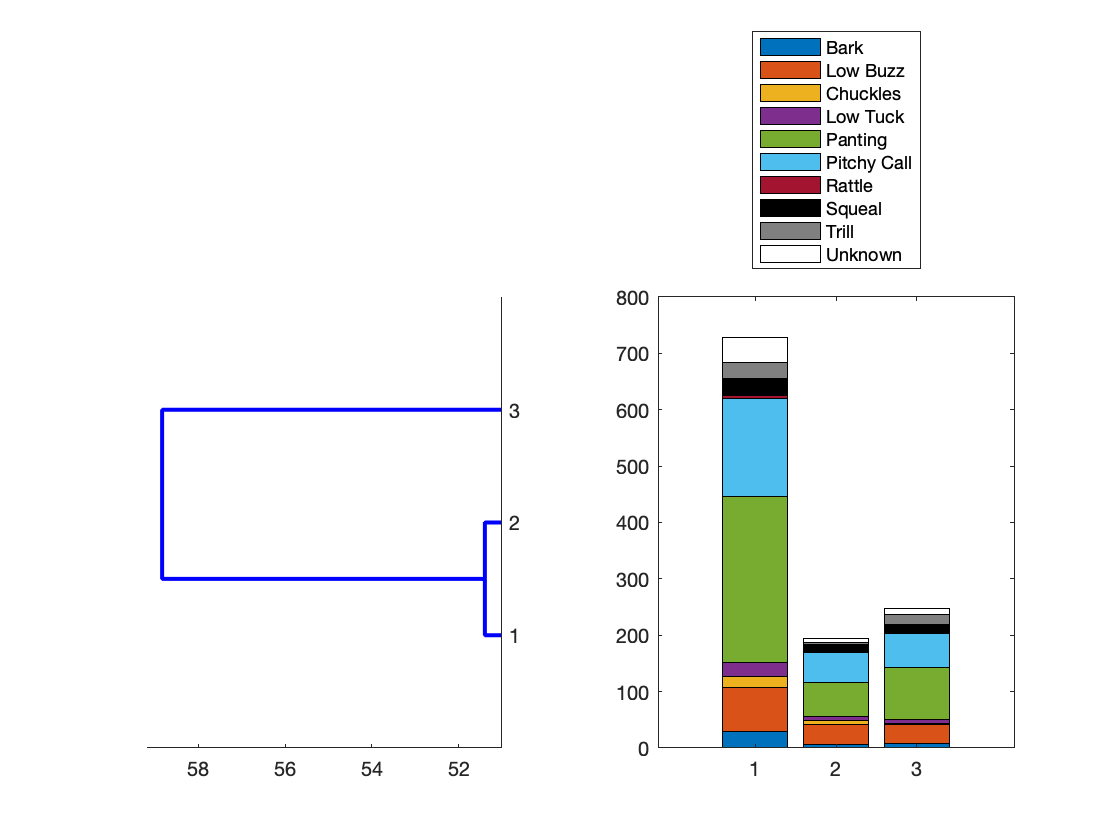

figure()
t=tiledlayout(1,2);
CTin3Cluster = nan(3,10);
nexttile
[D3, T3, ~] = dendrogram(Z,3, 'ColorThreshold','Default','Orientation','left');
set(D3,'LineWidth',2)
for cc=1:3
    for ct=1:length(UCT)
        CTin3Cluster(cc,ct) = sum(strcmp(CallType(T3==cc), UCT{ct}));
    end
end
nexttile
B= bar(CTin3Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

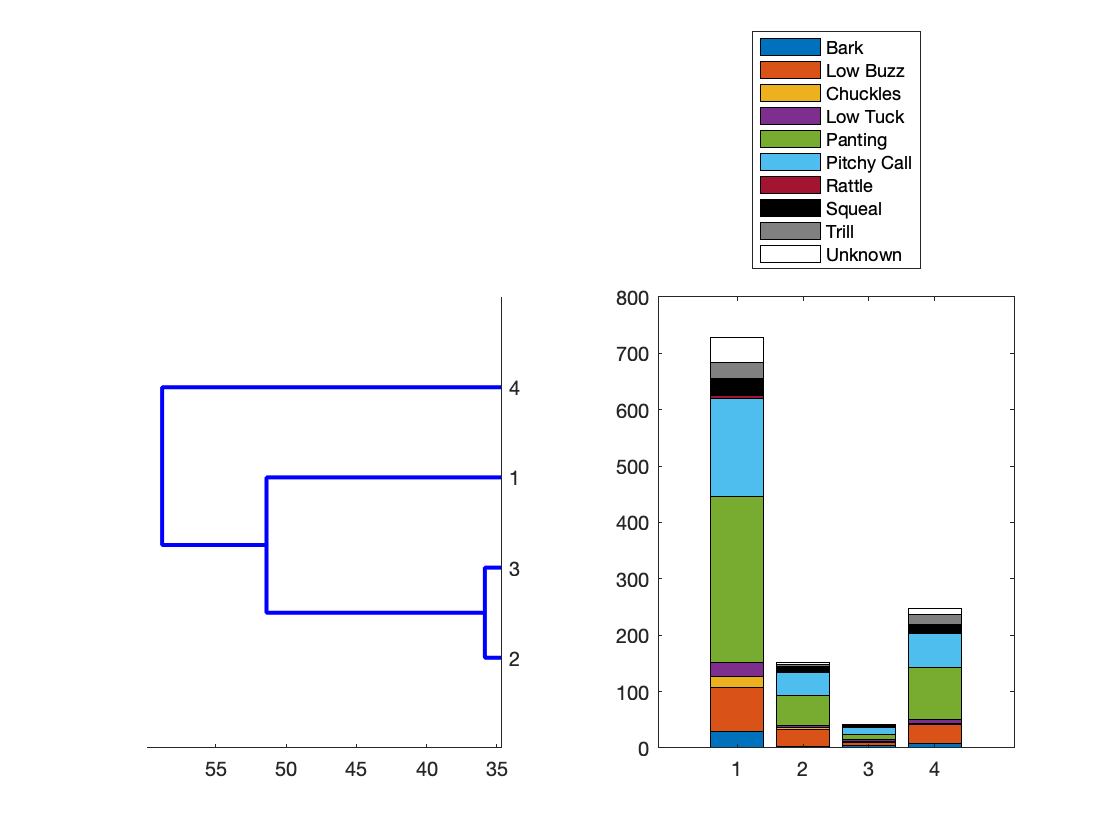

figure()
t=tiledlayout(1,2);
CTin4Cluster = nan(4,10);
nexttile
[D4, T4, ~] = dendrogram(Z,4, 'ColorThreshold','Default','Orientation','left');
set(D4,'LineWidth',2)
for cc=1:4
    for ct=1:length(UCT)
        CTin4Cluster(cc,ct) = sum(strcmp(CallType(T4==cc), UCT{ct}));
    end
end
nexttile
B= bar(CTin4Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

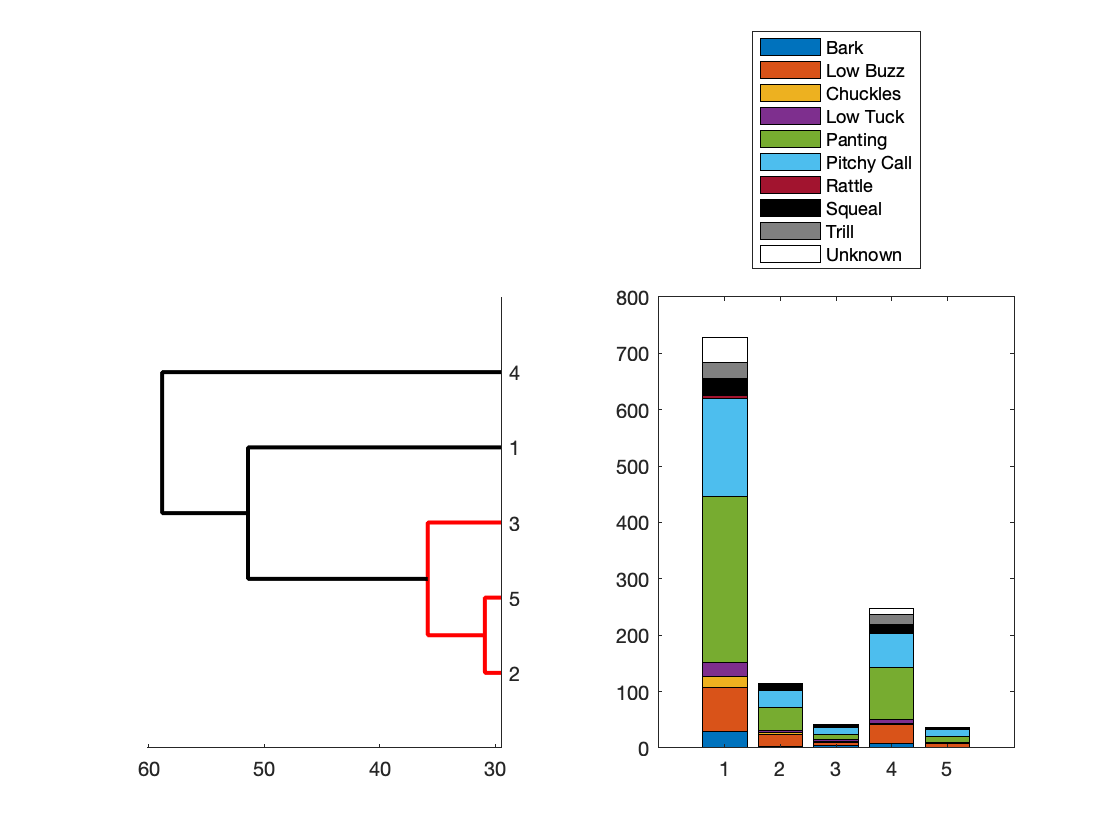

figure()
t=tiledlayout(1,2);
CTin5Cluster = nan(5,10);
nexttile
[D5, T5, ~] = dendrogram(Z,5, 'ColorThreshold','Default','Orientation','left');
set(D5,'LineWidth',2)
for cc=1:5
    for ct=1:length(UCT)
        CTin5Cluster(cc,ct) = sum(strcmp(CallType(T5==cc), UCT{ct}));
    end
end
nexttile
B= bar(CTin5Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

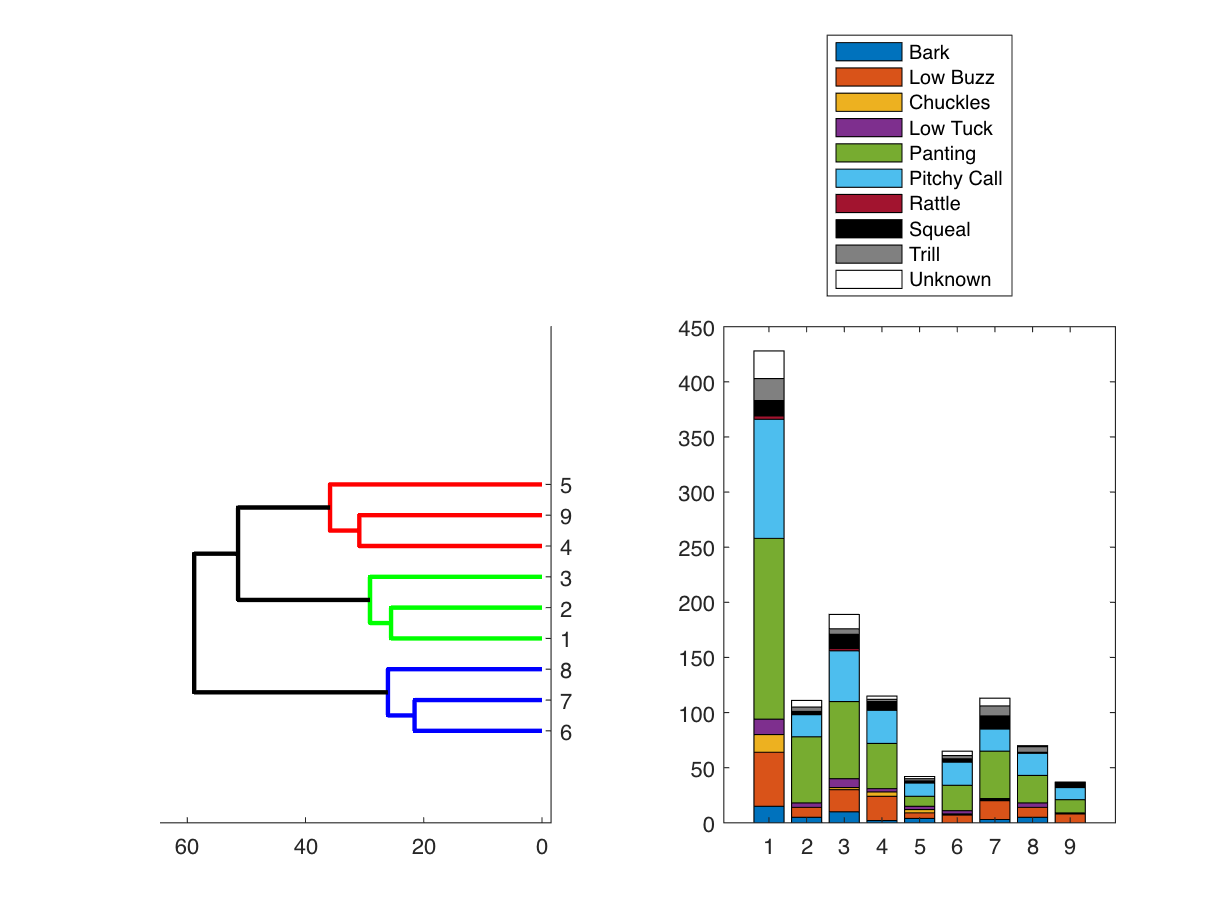

figure()
t=tiledlayout(1,2);
CTin9Cluster = nan(9,10);
nexttile
[D9, T9, ~] = dendrogram(Z,9, 'ColorThreshold','Default','Orientation','left');
set(D9,'LineWidth',2)
for cc=1:9
    for ct=1:length(UCT)
        CTin9Cluster(cc,ct) = sum(strcmp(CallType(T9==cc), UCT{ct}));
    end
end
nexttile
B= bar(CTin9Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

Try some UMAP projections of the PAF

NNeigh = 10;
MinDist = 0.051;
[Reduction,UMAP]= run_umap(DataTable1, 'metric','euclidean','n_component',3,'target_weight',0.55, 'n_neighbors',NNeigh, 'min_dist',MinDist);

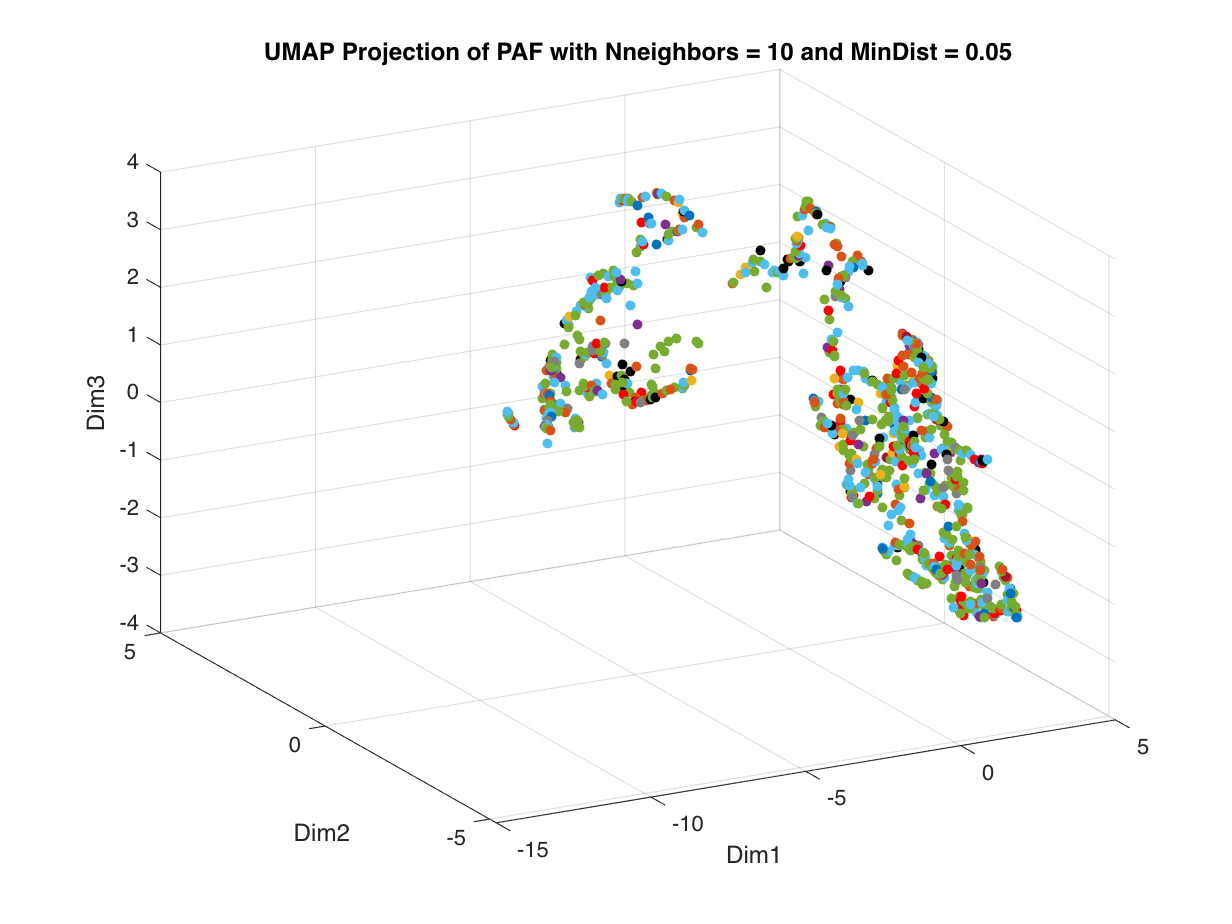

figure()
CallType_local = CallType(~isnan(F0_mean));
scatter3(Reduction(~strcmp(CallType_local, 'Un'),1), Reduction(~strcmp(CallType_local, 'Un'),2),Reduction(~strcmp(CallType_local, 'Un'),3),20,CCT(~strcmp(CallType_local, 'Un'),:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Projection of PAF with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

function [MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<6
        Log=1;
    end

    if nargin<7
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<8
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<5
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    colorbar()
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_local*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end